## Cue only ! dummy coding

## Pain  cue

#### Pain :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0018.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel/sub-0003/con_0018.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 24360228 bytes
Loading image number:    61
Elapsed time is 151.664213 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 5934270  Bit rate: 22.50 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C', 'cueXcue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C', 'stimXcue_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C'};

#### Pain :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              06:44:19 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Pain :: Plot diagnostics, before l2norm

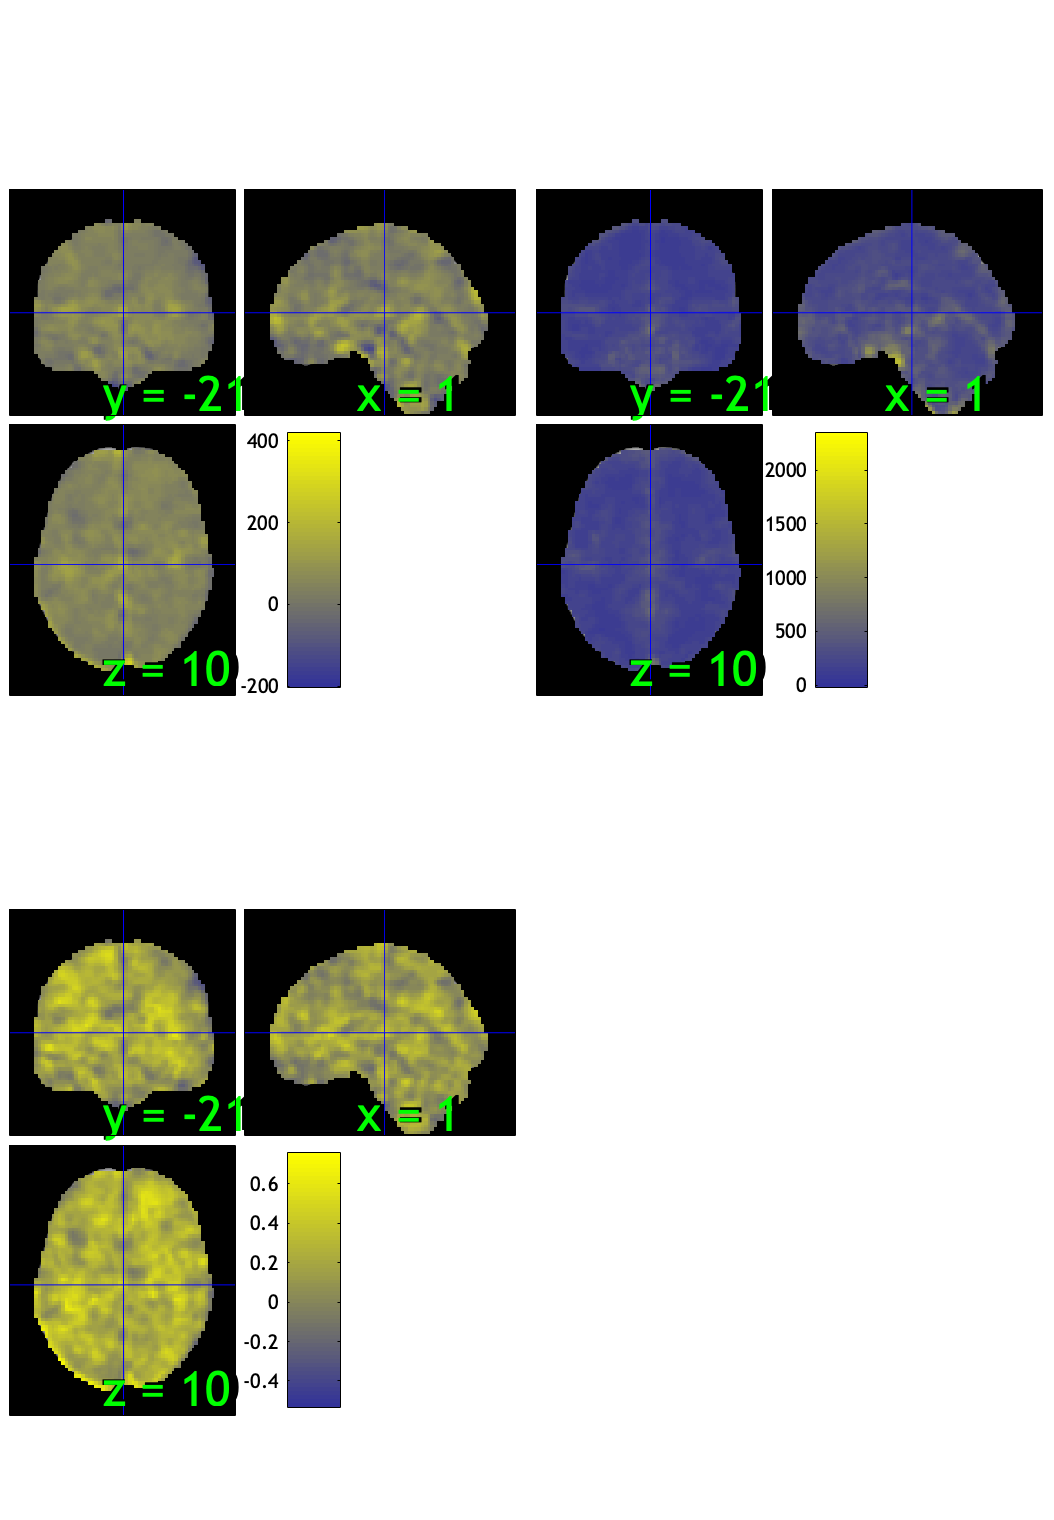

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 24.59%
Expected 3.05 outside 95% ellipsoid, found  11

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 8 images		Cases 5 10 14 28 31 37 40 57 
Uncorrected: 11 images		Cases 5 10 14 21 28 31 37 40 44 55 57 

Retained 15 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 54.10%
Expected 3.05 outside 95% ellipsoid, found   4

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 4 images		Cases 1 14 28 54 

Mahalanobis (cov and corr, q<0.05 corrected):
  8 images 
                               Outlier_count    Percentage

SPM12: spm_check_registration (v7759)              06:44:57 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

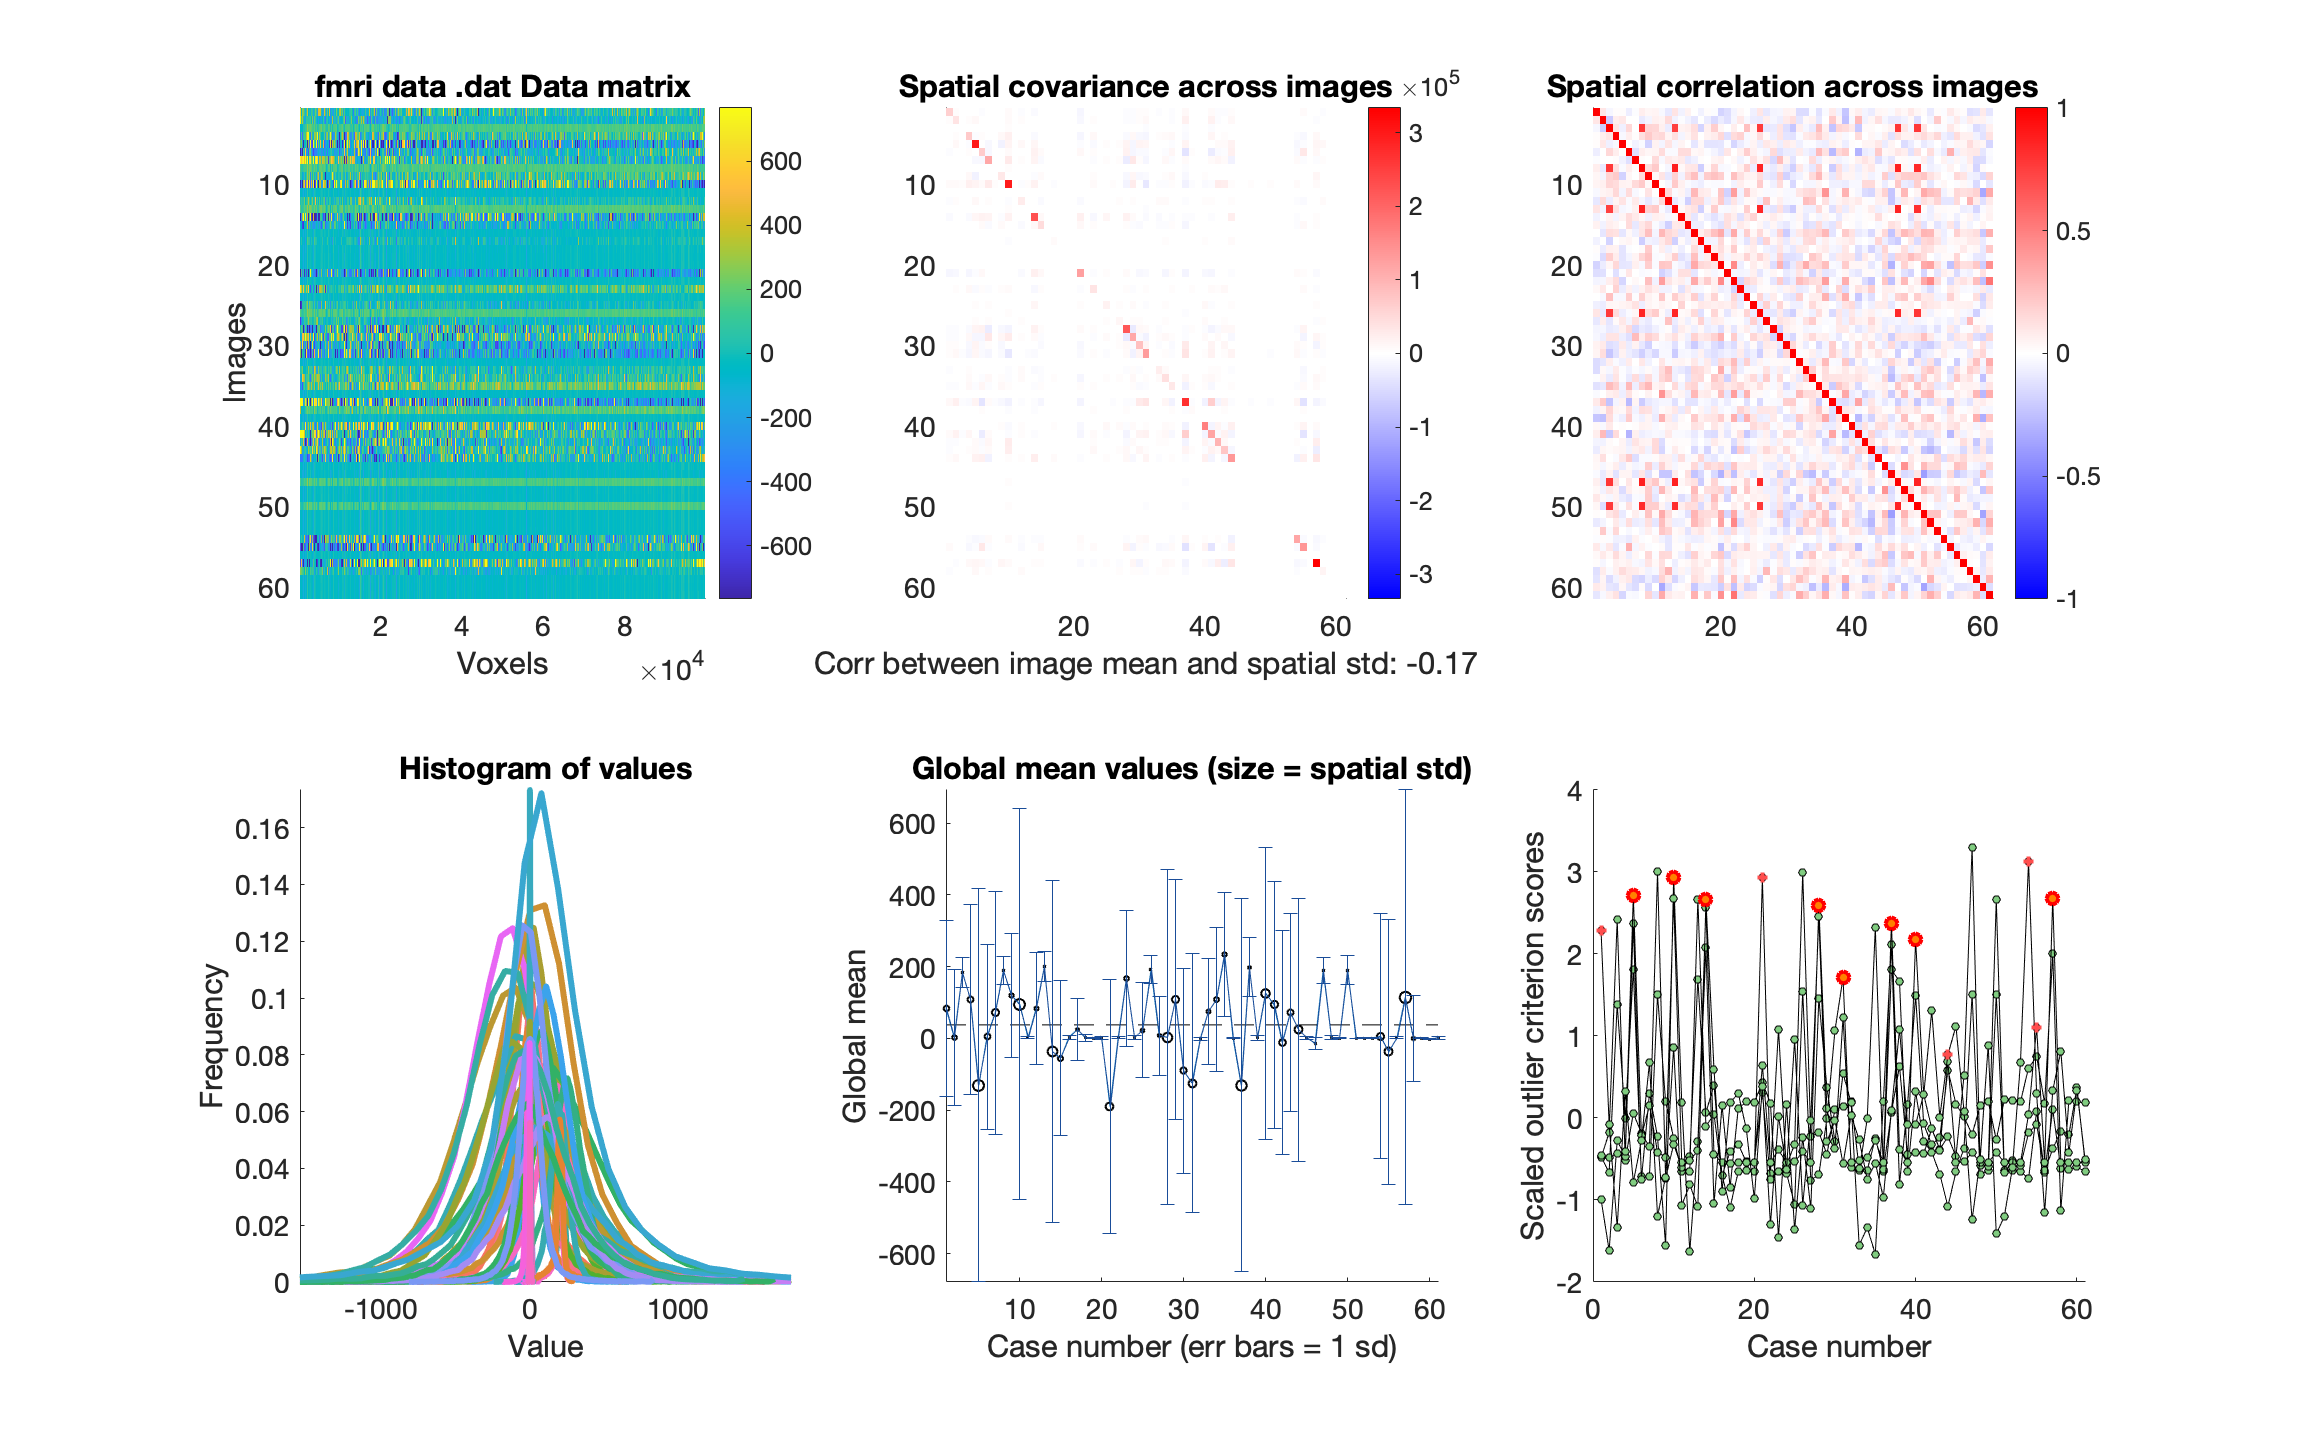

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


wh_outlier_uncorr = 61×1 logical array
   1
   0
   0
   0
   1
   0
   0
   0
   0
   1


wh_outlier_corr = 61×1 logical array
   0
   0
   0
   0
   1
   0
   0
   0
   0
   1


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Pain :: run robfit

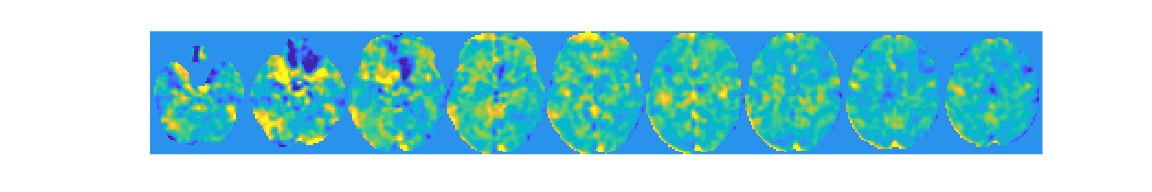

set(gcf,'Visible','on')

figure ('Visible', 'on');
drawnow, snapnow;

#### Pain :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 61


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×53 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [53×12 char]
              fullpath: [61×109 char]
           files_exist: [61×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×53 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [53×12 char]
              fullpath: [53×109 char]
           files_exist: [61×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×53 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [53×12 char]
              fullpath: [53×109 char]
           files_exist: [53×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 8 participants, size is now 53


#### Pain :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


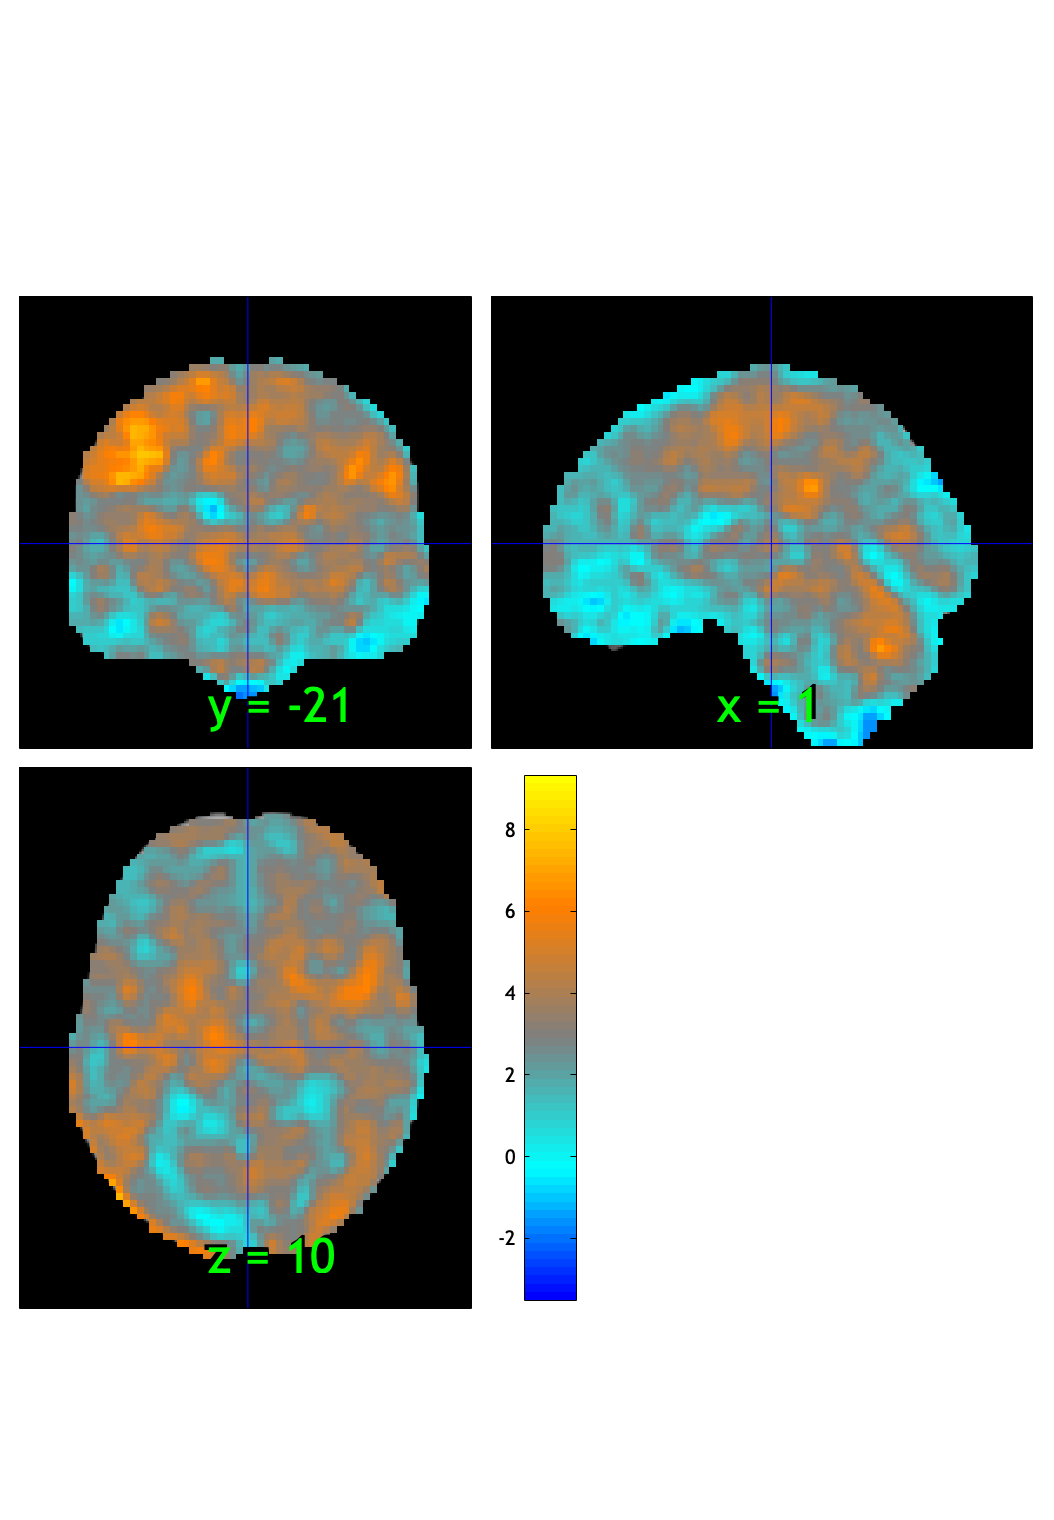

SPM12: spm_check_registration (v7759)              06:45:03 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t)

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.035550

Image   1
 10 contig. clusters, sizes   1 to 70885
Positive effect: 70916 voxels, min p-value: 0.00000000
Negative effect:  72 voxels, min p-value: 0.00128245


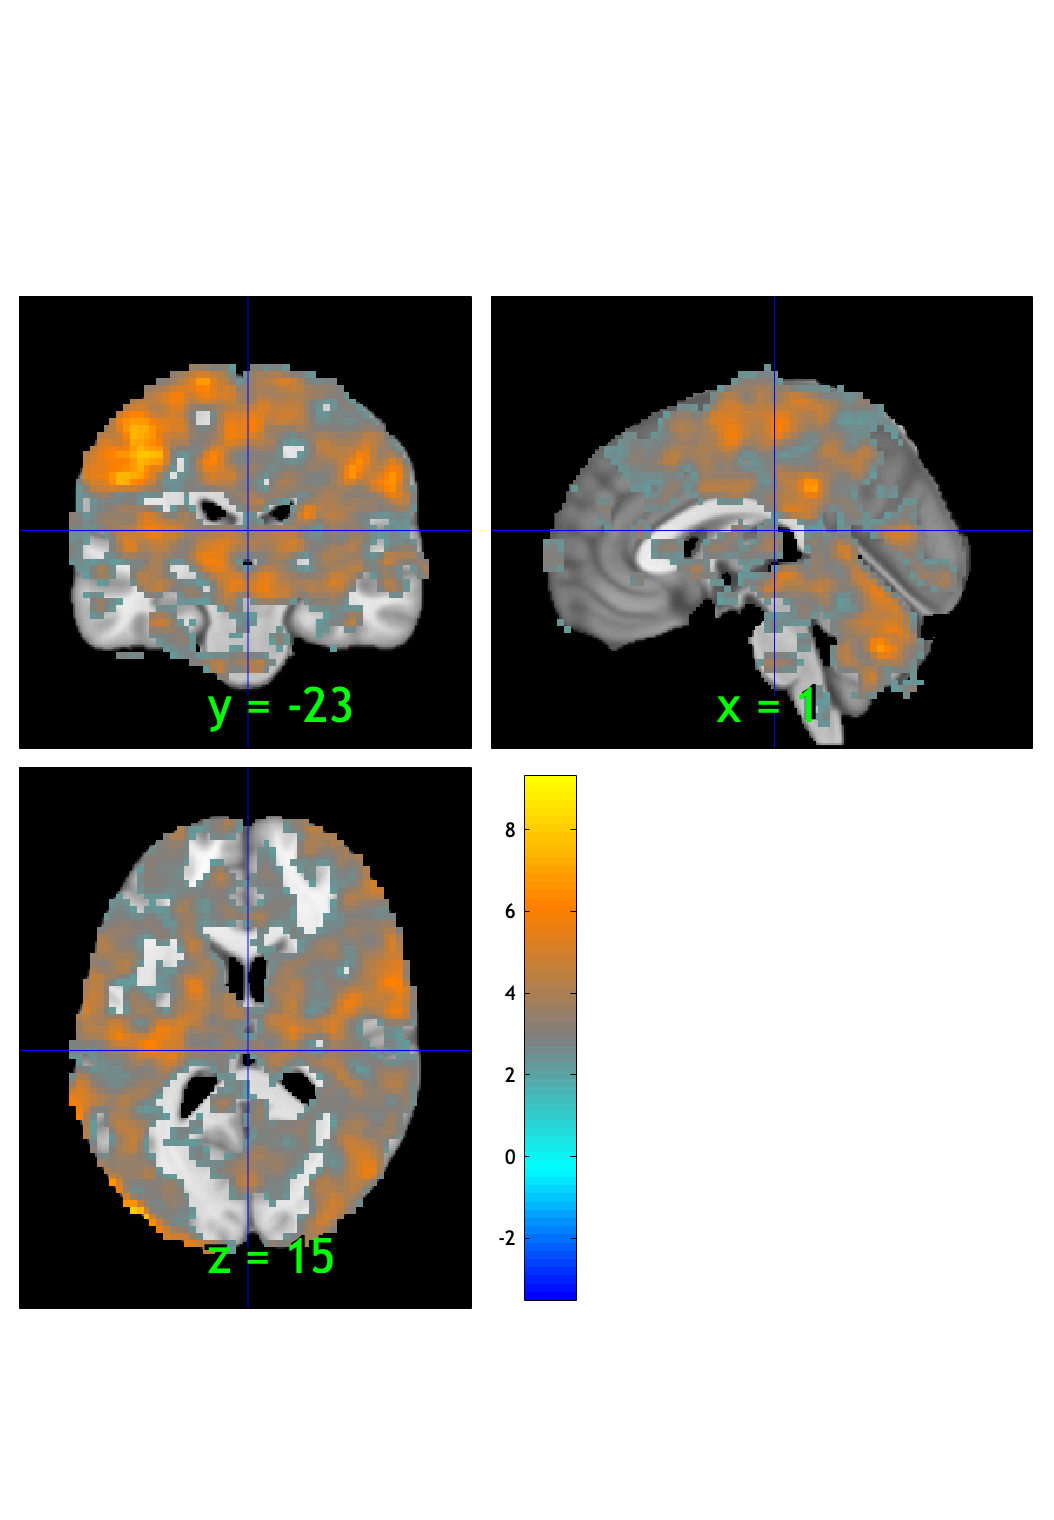

SPM12: spm_check_registration (v7759)              06:45:05 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×10 struct}


orthviews(fdr_t)

drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)

Setting up fmridisplay objects


sagittal montage: 1274 voxels displayed, 69714 not displayed on these slices


sagittal montage: 1607 voxels displayed, 69381 not displayed on these slices


sagittal montage: 1261 voxels displayed, 69727 not displayed on these slices


axial montage: 13318 voxels displayed, 57670 not displayed on these slices


axial montage: 14118 voxels displayed, 56870 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


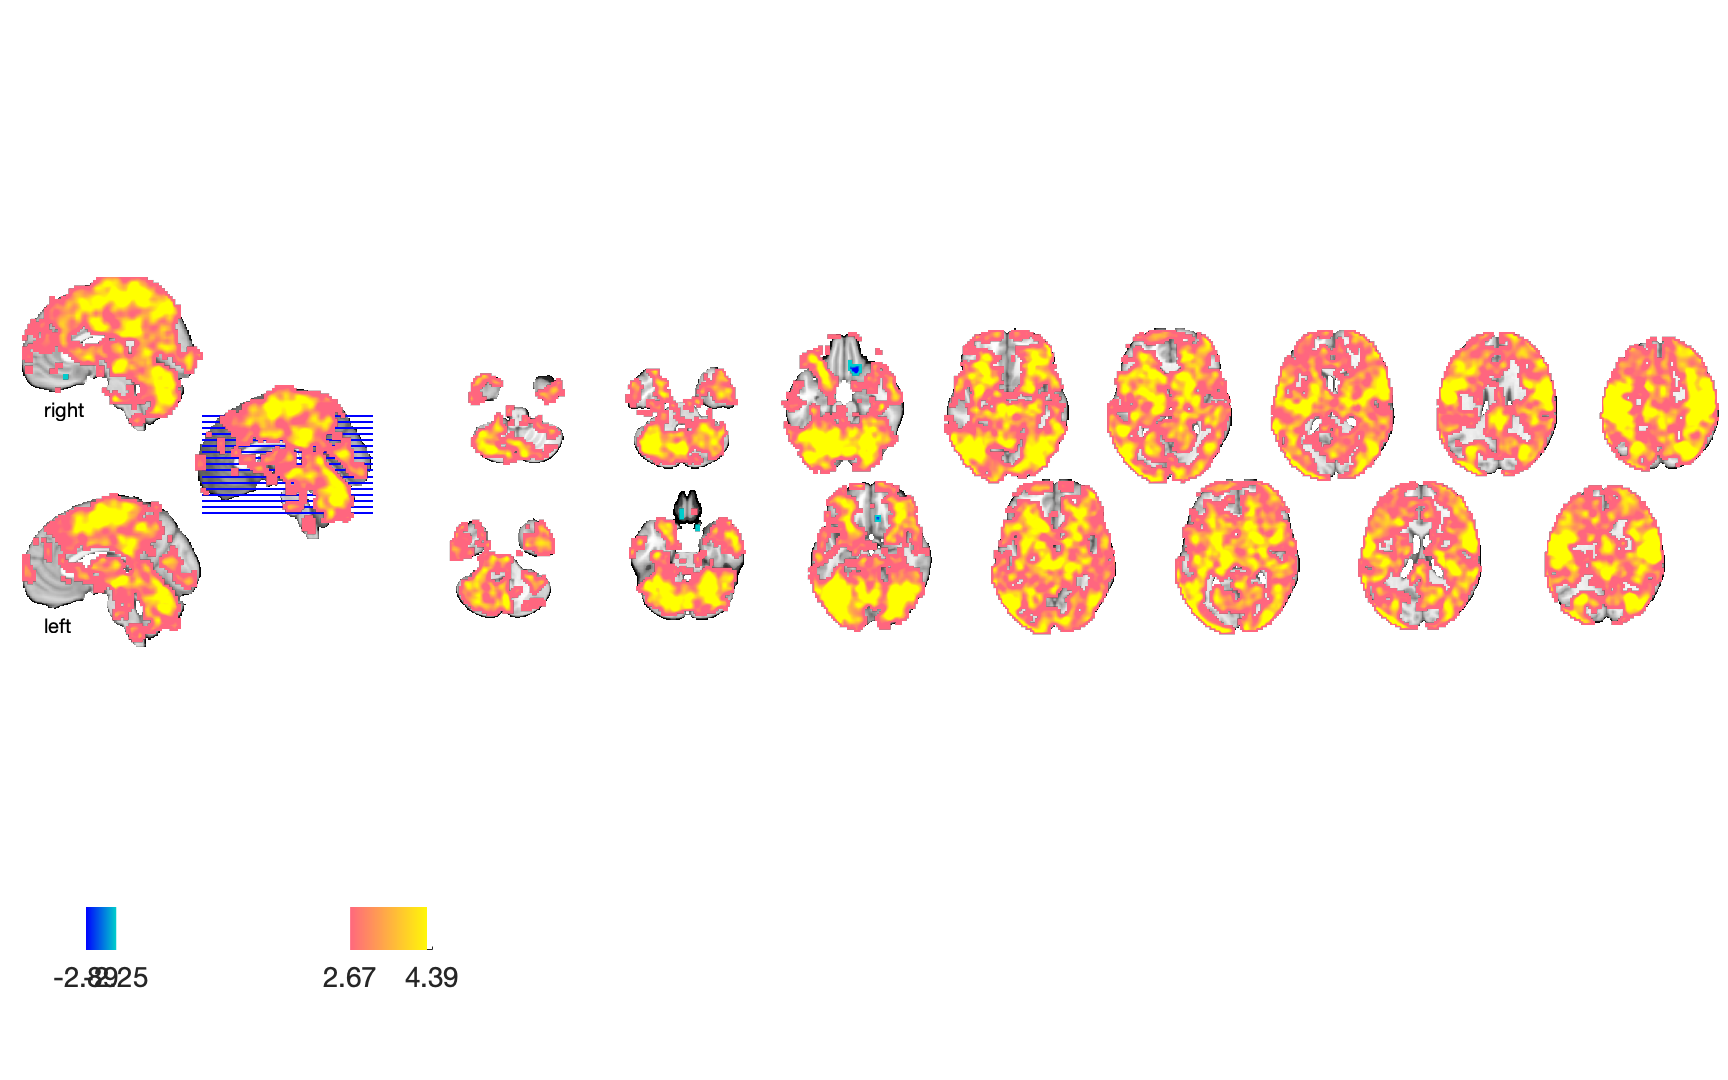

drawnow, snapnow;

## Vicarious  cue

clear all

#### Vicarious  :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0019.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel/sub-0003/con_0019.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 24360228 bytes
Loading image number:    61
Elapsed time is 162.831692 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 5951534  Bit rate: 22.50 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C', 'cueXcue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C', 'stimXcue_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C'};

#### Vicarious  :: `check data coverage`

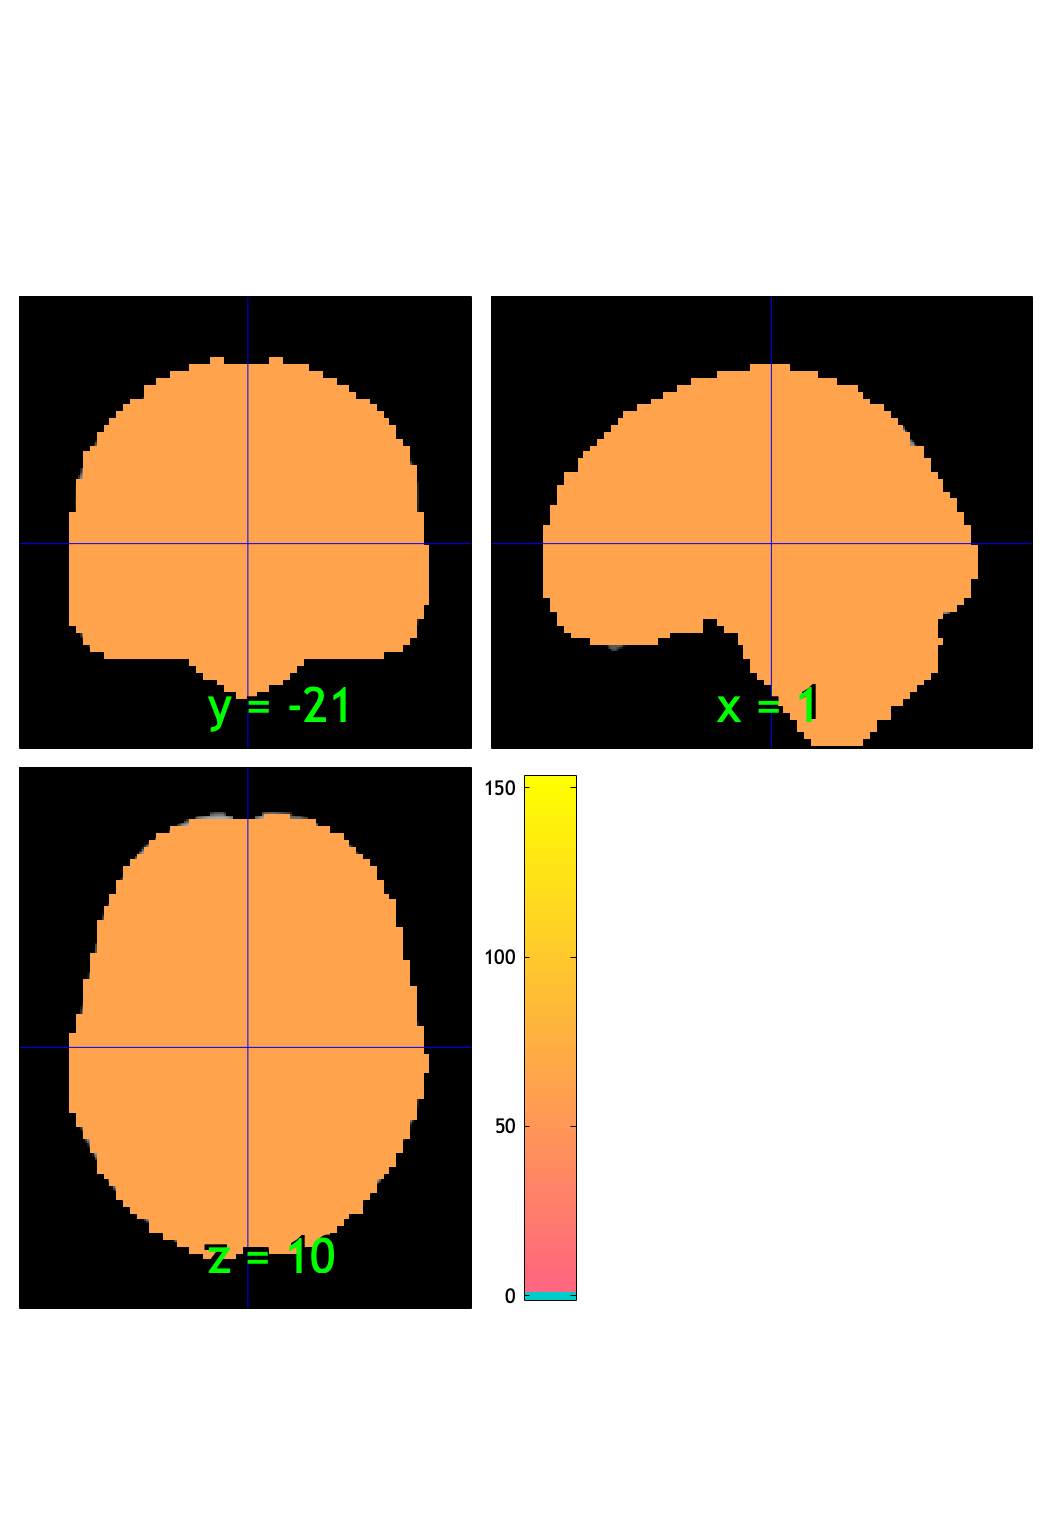

SPM12: spm_check_registration (v7759)              06:48:19 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### Vicarious  :: Plot diagnostics, before l2norm

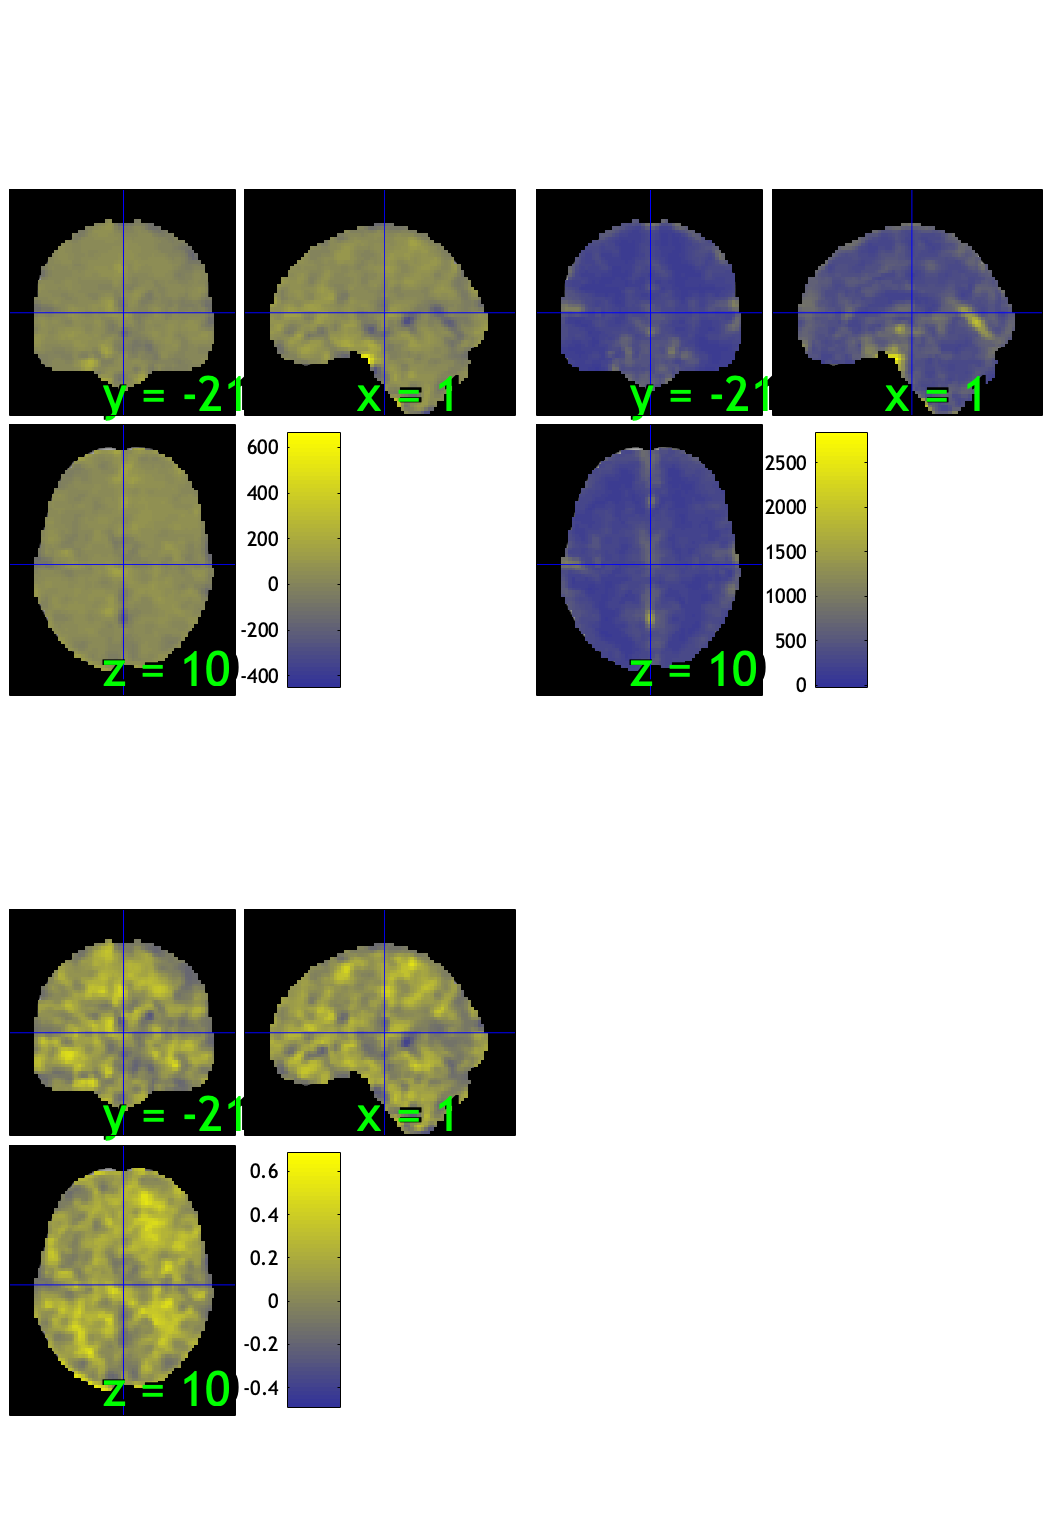

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 18.03%
Expected 3.05 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 5 images		Cases 10 28 29 50 57 
Uncorrected: 6 images		Cases 10 19 28 29 50 57 

Retained 17 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 50.82%
Expected 3.05 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Mahalanobis (cov and corr, q<0.05 corrected):
  5 images 
                               Outlier_count    Percentage
                              

SPM12: spm_check_registration (v7759)              06:48:57 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

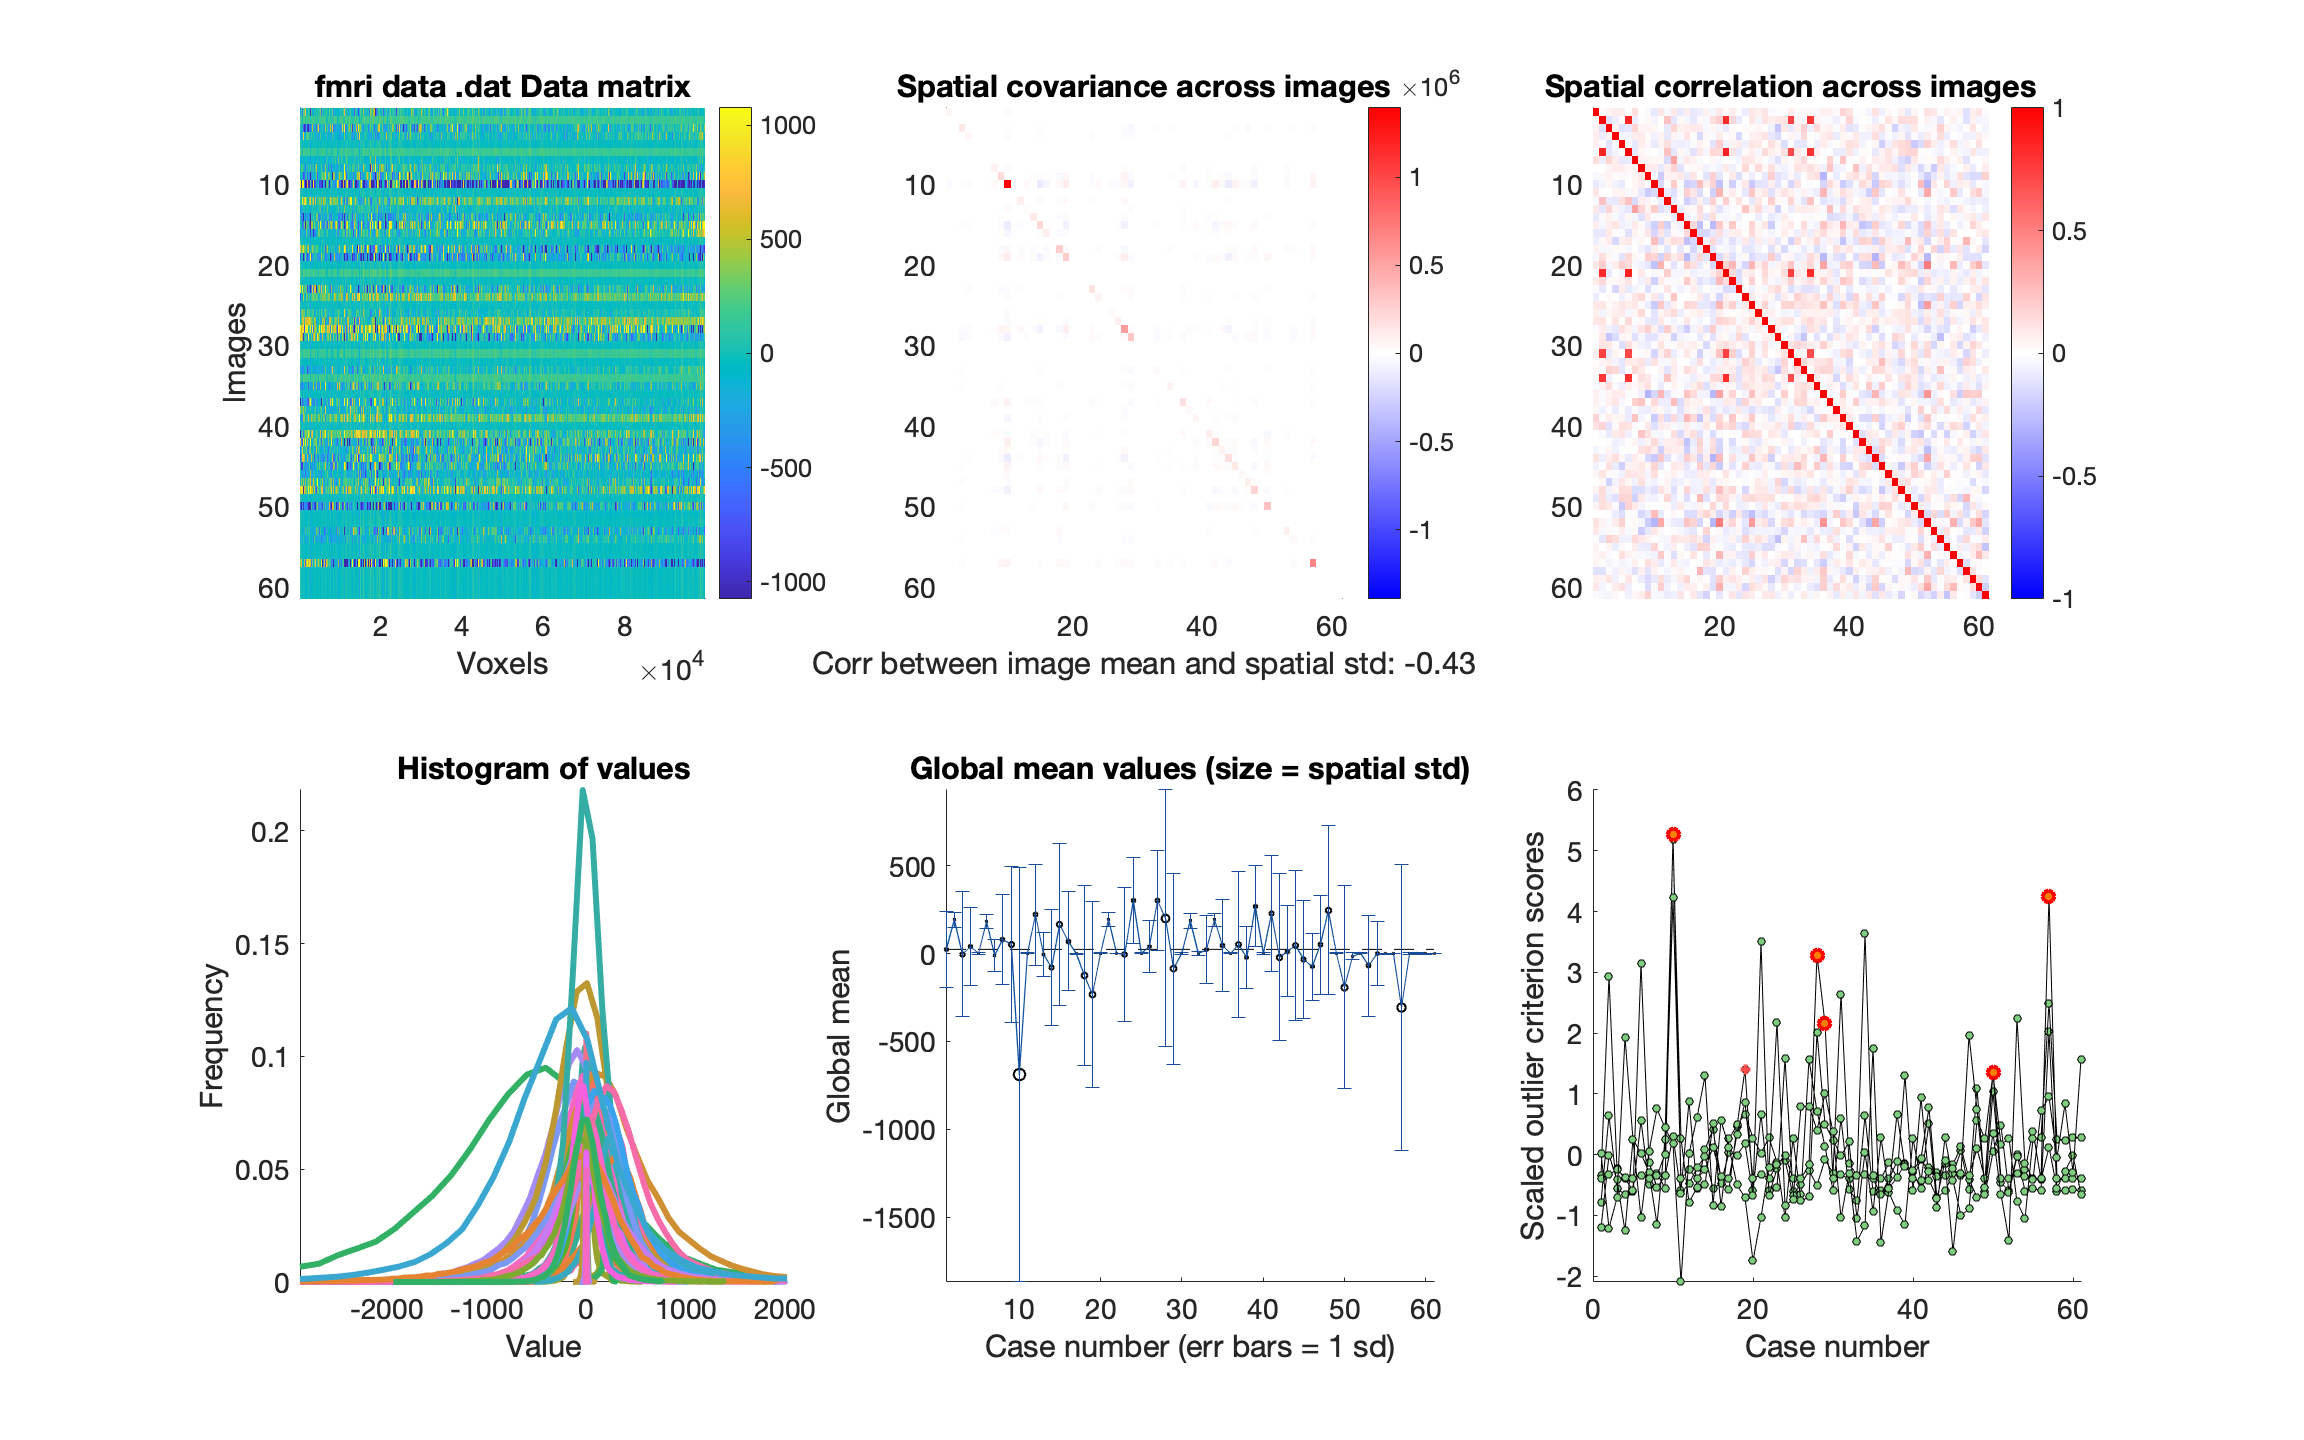

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


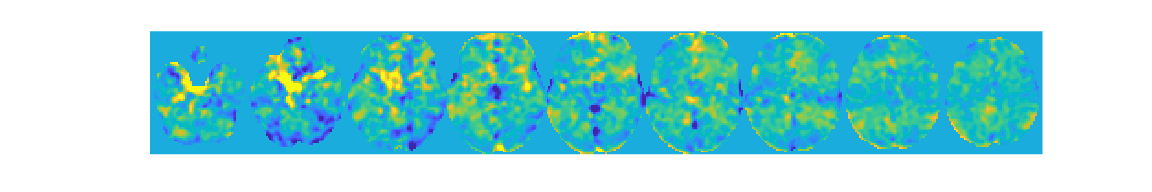

wh_outlier_uncorr = 61×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1


wh_outlier_corr = 61×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Vicarious  :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious  :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 61


%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×56 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [56×12 char]
              fullpath: [61×109 char]
           files_exist: [61×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×56 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [56×12 char]
              fullpath: [56×109 char]
           files_exist: [61×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×56 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [56×12 char]
              fullpath: [56×109 char]
           files_exist: [56×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 5 participants, size is now 56


#### Vicarious  :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious  :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


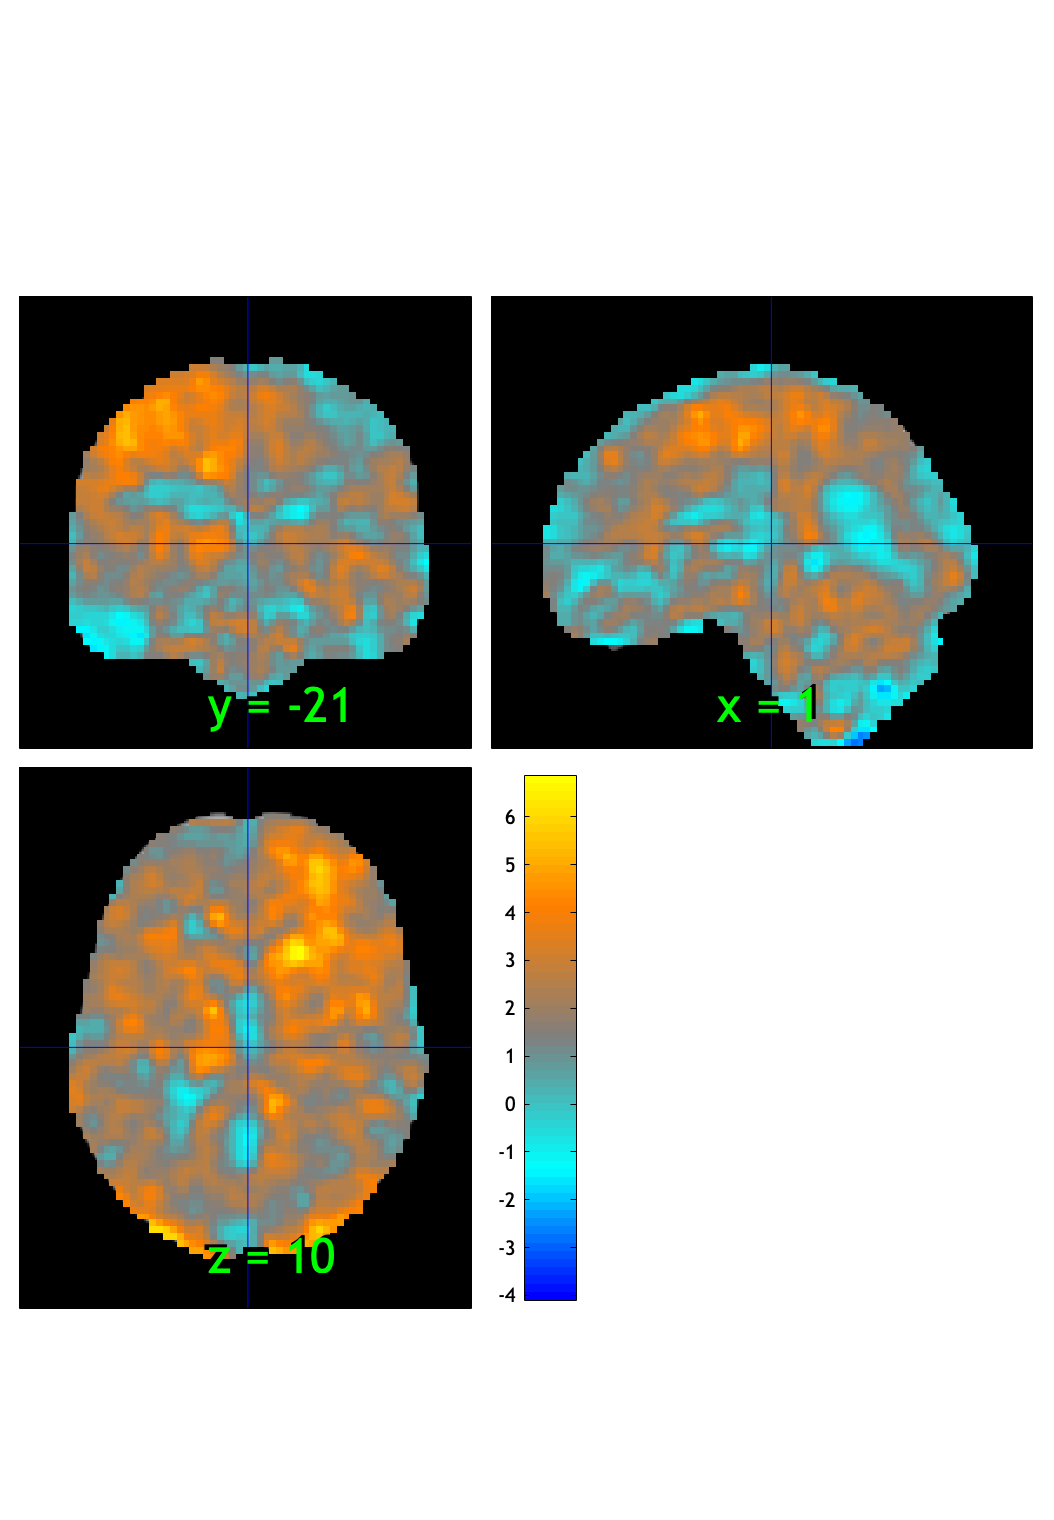

SPM12: spm_check_registration (v7759)              06:49:03 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t)

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.016120

Image   1
 66 contig. clusters, sizes   1 to 31290
Positive effect: 32077 voxels, min p-value: 0.00000000
Negative effect: 116 voxels, min p-value: 0.00018430


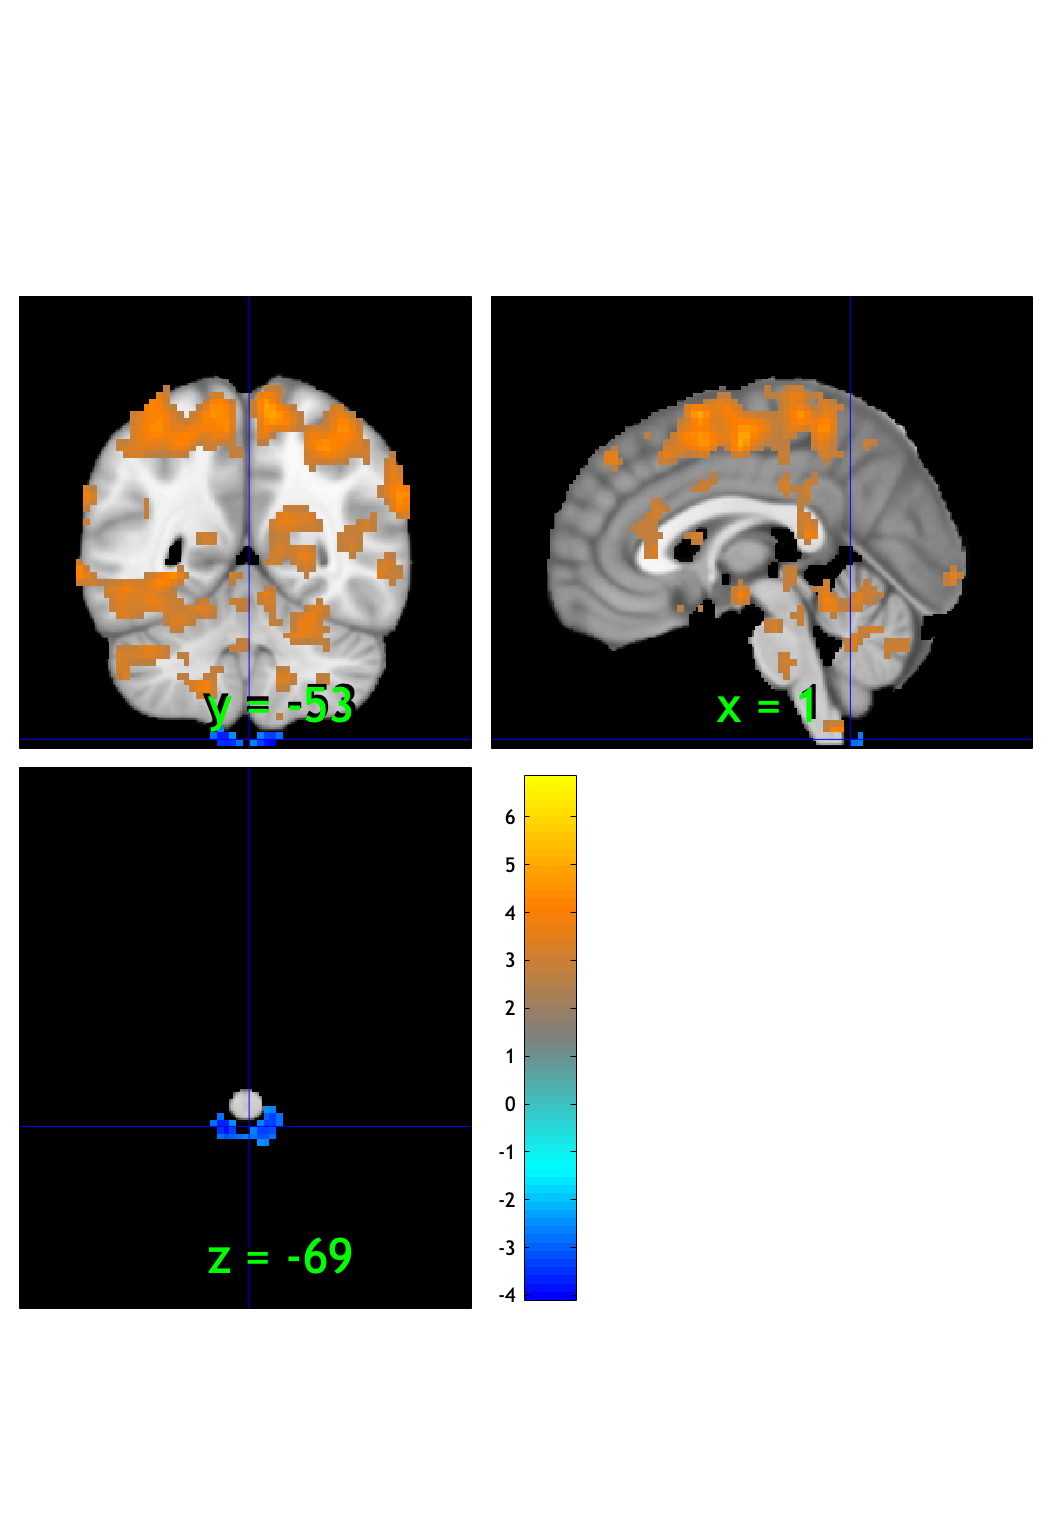

SPM12: spm_check_registration (v7759)              06:49:04 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×66 struct}


orthviews(fdr_t)

drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)

Setting up fmridisplay objects


sagittal montage: 453 voxels displayed, 31740 not displayed on these slices


sagittal montage: 638 voxels displayed, 31555 not displayed on these slices


sagittal montage: 391 voxels displayed, 31802 not displayed on these slices


axial montage: 5805 voxels displayed, 26388 not displayed on these slices


axial montage: 6364 voxels displayed, 25829 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


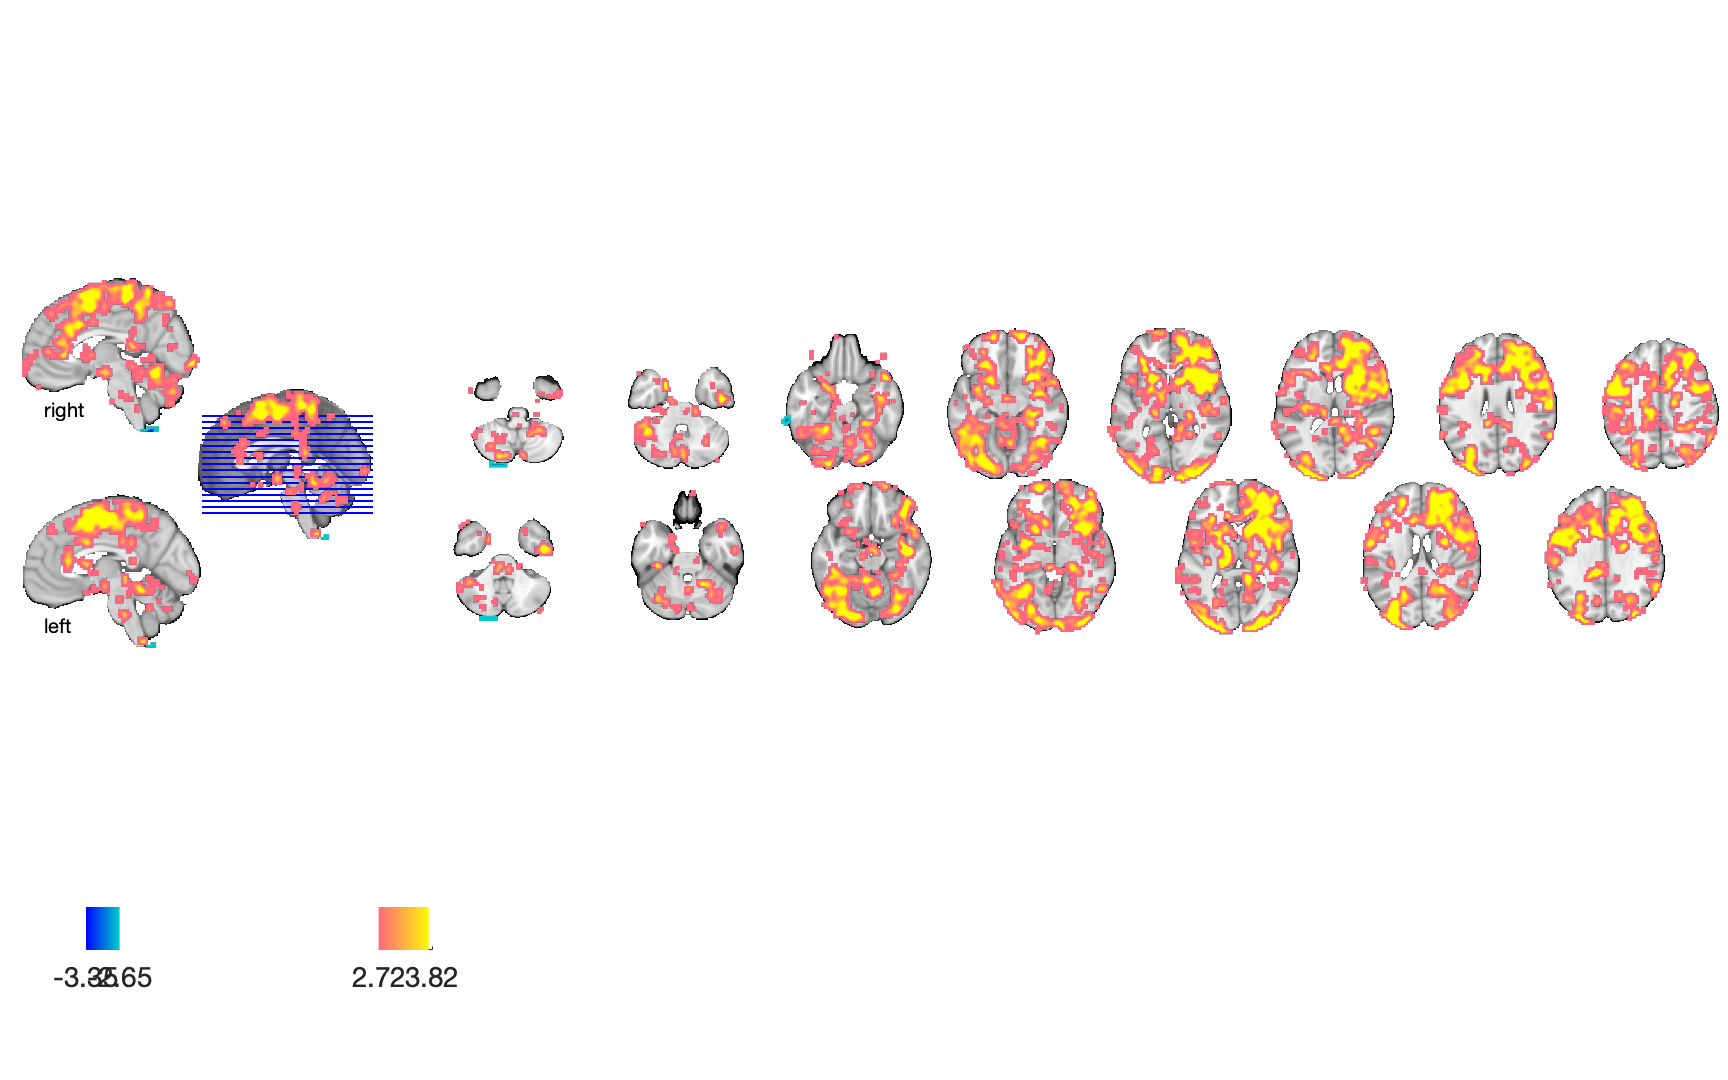

drawnow, snapnow;

## Cognitive cue

#### Cognitive :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0020.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel/sub-0003/con_0020.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 24360228 bytes
Loading image number:    61
Elapsed time is 162.035662 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 5940111  Bit rate: 22.50 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C', 'cueXcue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C', 'stimXcue_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C'};

#### Cognitive :: `check data coverage`

SPM12: spm_check_registration (v7759)              06:52:21 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### Cognitive :: Plot diagnostics, before l2norm

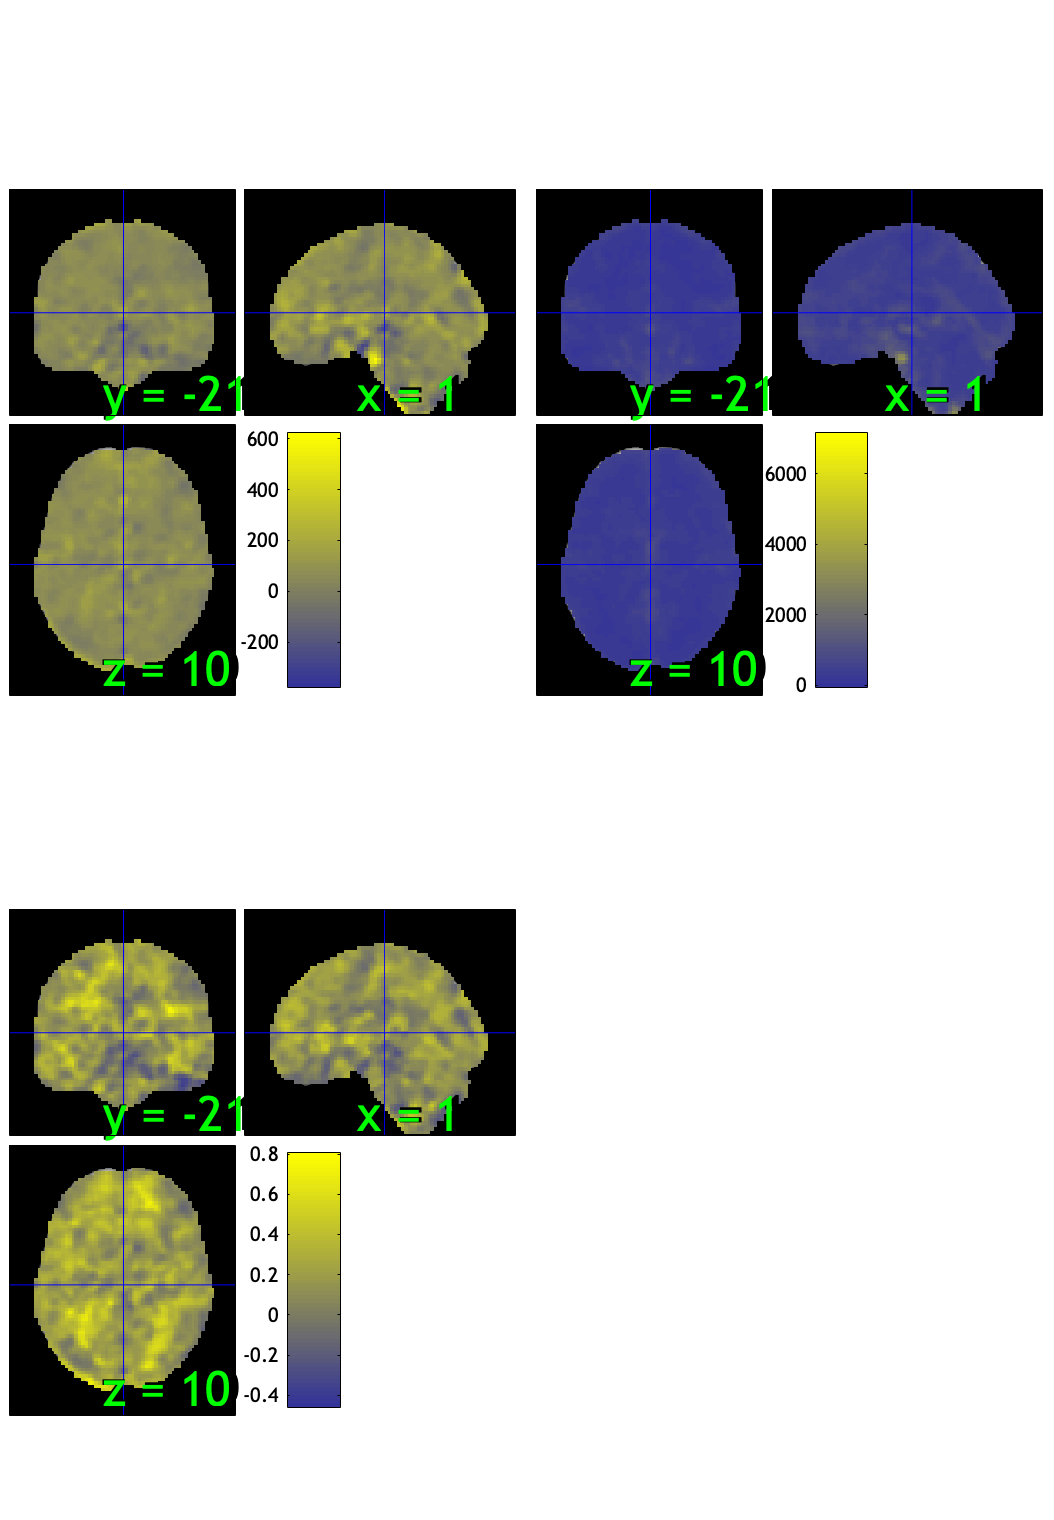

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 18.03%
Expected 3.05 outside 95% ellipsoid, found   4

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 4 images		Cases 8 21 26 27 
Uncorrected: 4 images		Cases 8 21 26 27 

Retained 17 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 47.54%
Expected 3.05 outside 95% ellipsoid, found   1

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 1 images		Cases 48 

Mahalanobis (cov and corr, q<0.05 corrected):
  4 images 
                               Outlier_count    Percentage
                               

SPM12: spm_check_registration (v7759)              06:52:50 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

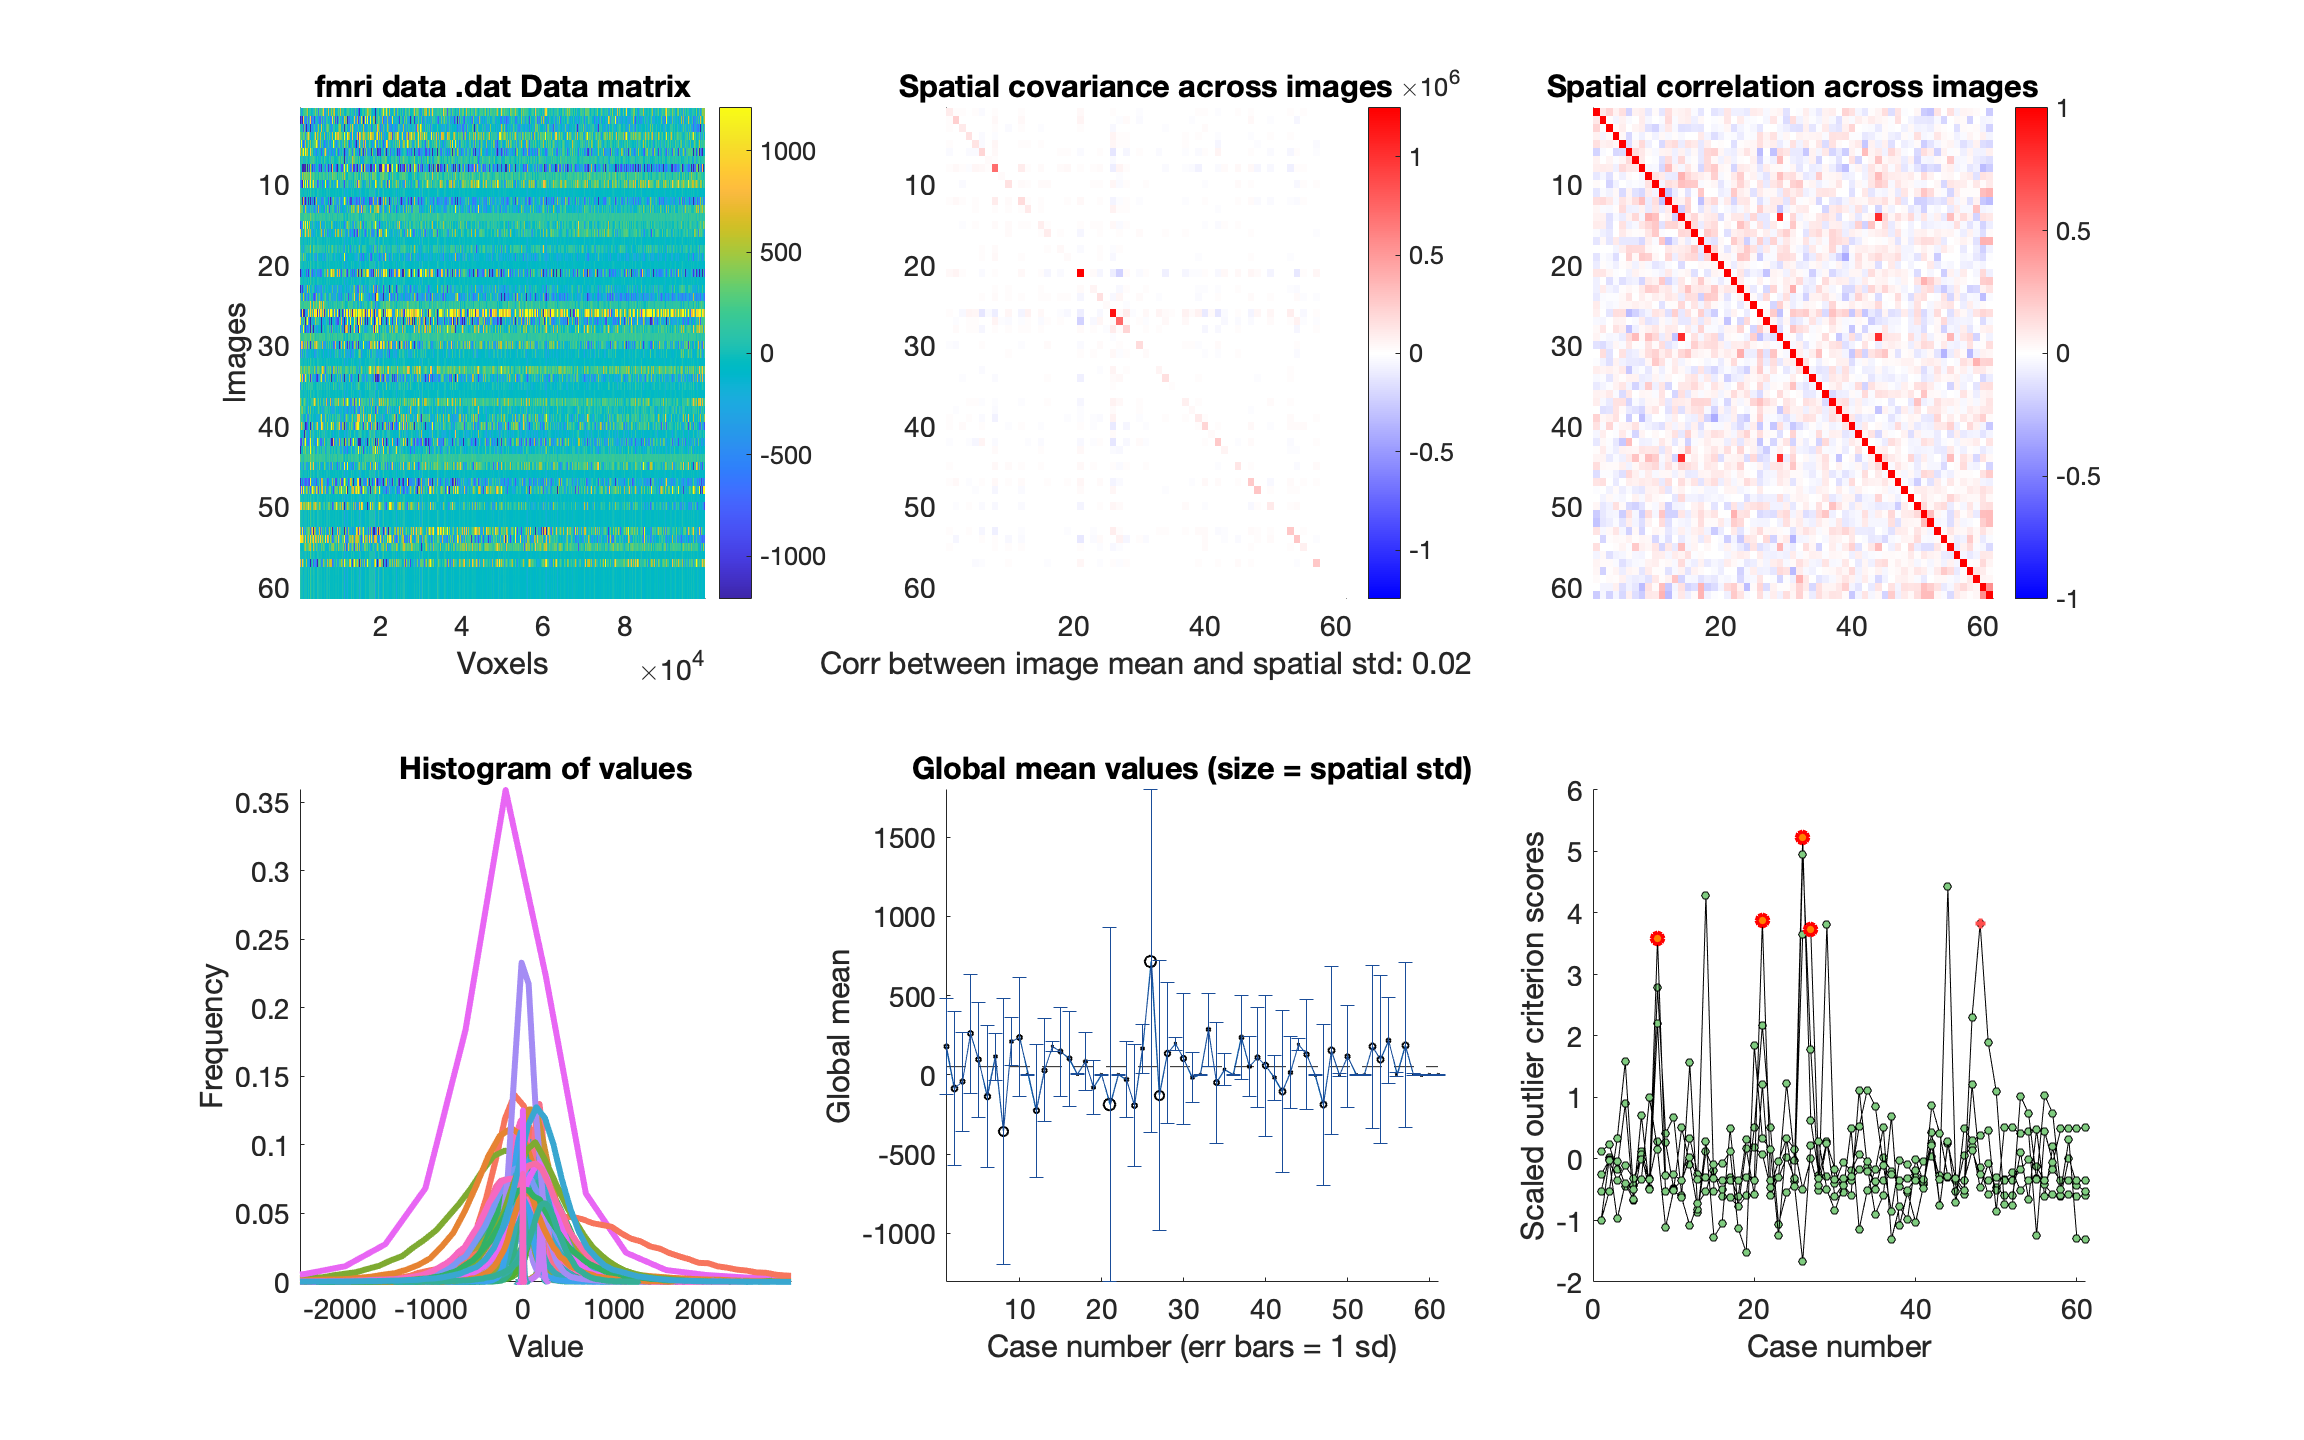

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


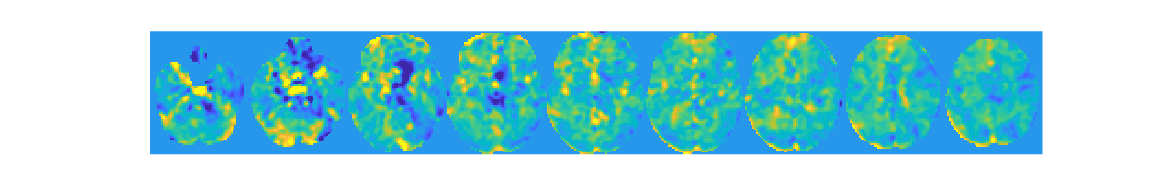

wh_outlier_uncorr = 61×1 logical array
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0


wh_outlier_corr = 61×1 logical array
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Cognitive :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 61


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×57 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [57×12 char]
              fullpath: [61×109 char]
           files_exist: [61×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×57 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [57×12 char]
              fullpath: [57×109 char]
           files_exist: [61×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×57 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [57×12 char]
              fullpath: [57×109 char]
           files_exist: [57×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 4 participants, size is now 57


#### Cognitive :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


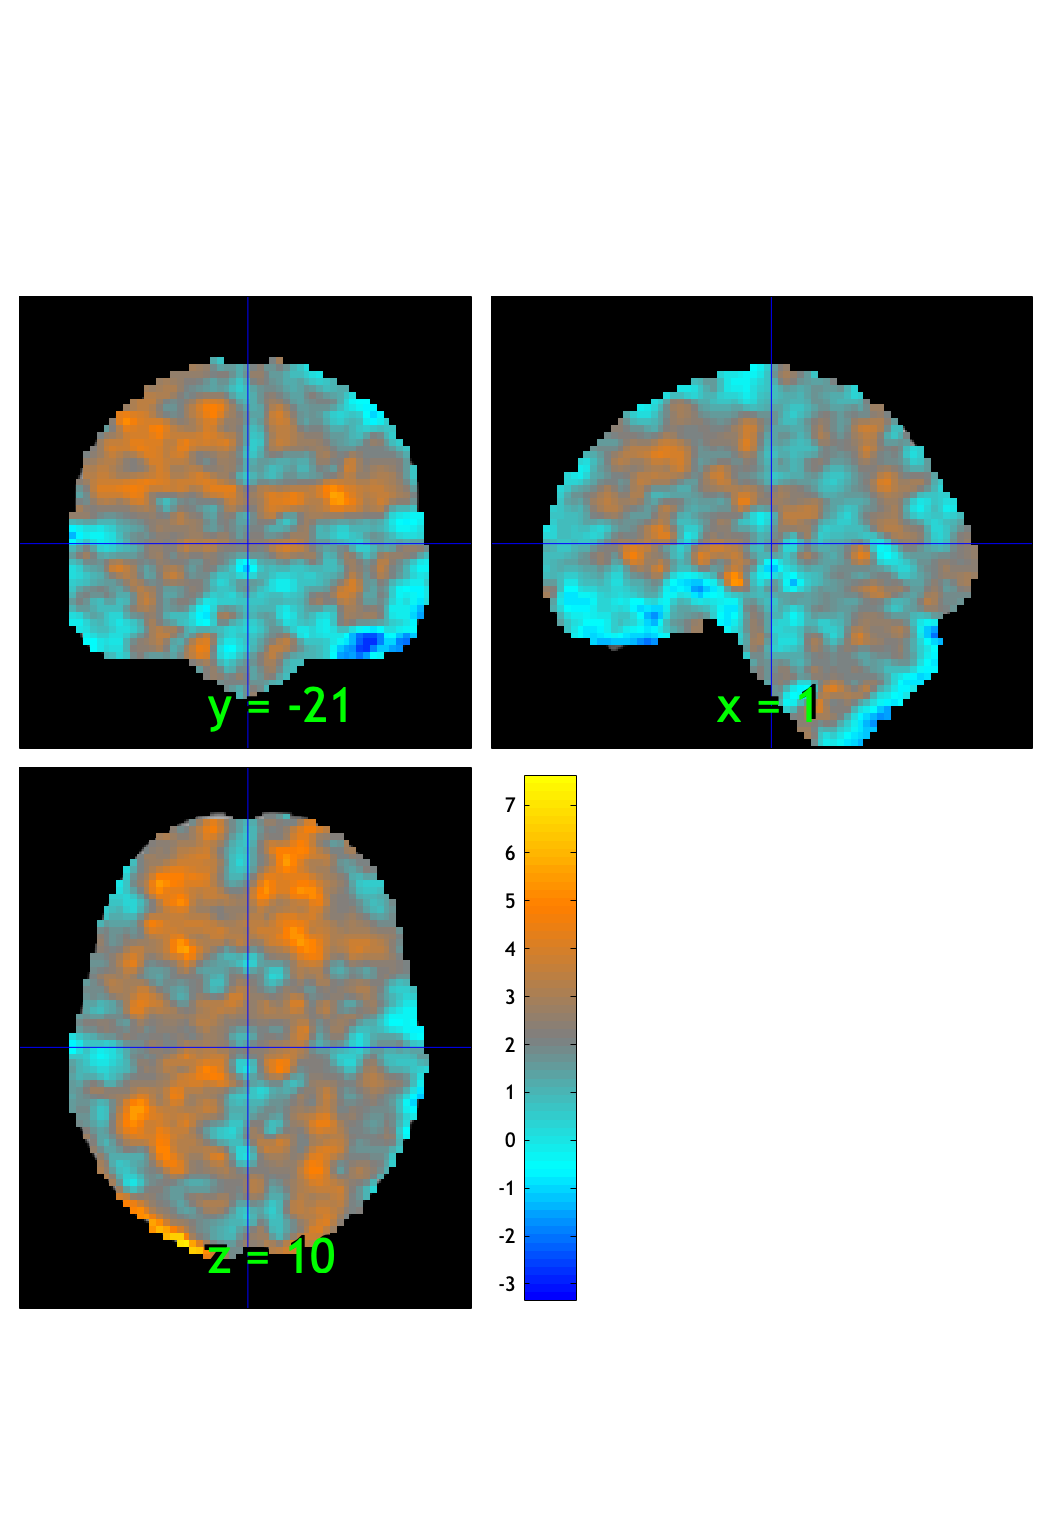

SPM12: spm_check_registration (v7759)              06:53:03 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t)

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.021671

Image   1
 46 contig. clusters, sizes   1 to 42845
Positive effect: 43207 voxels, min p-value: 0.00000000
Negative effect:  67 voxels, min p-value: 0.00196159


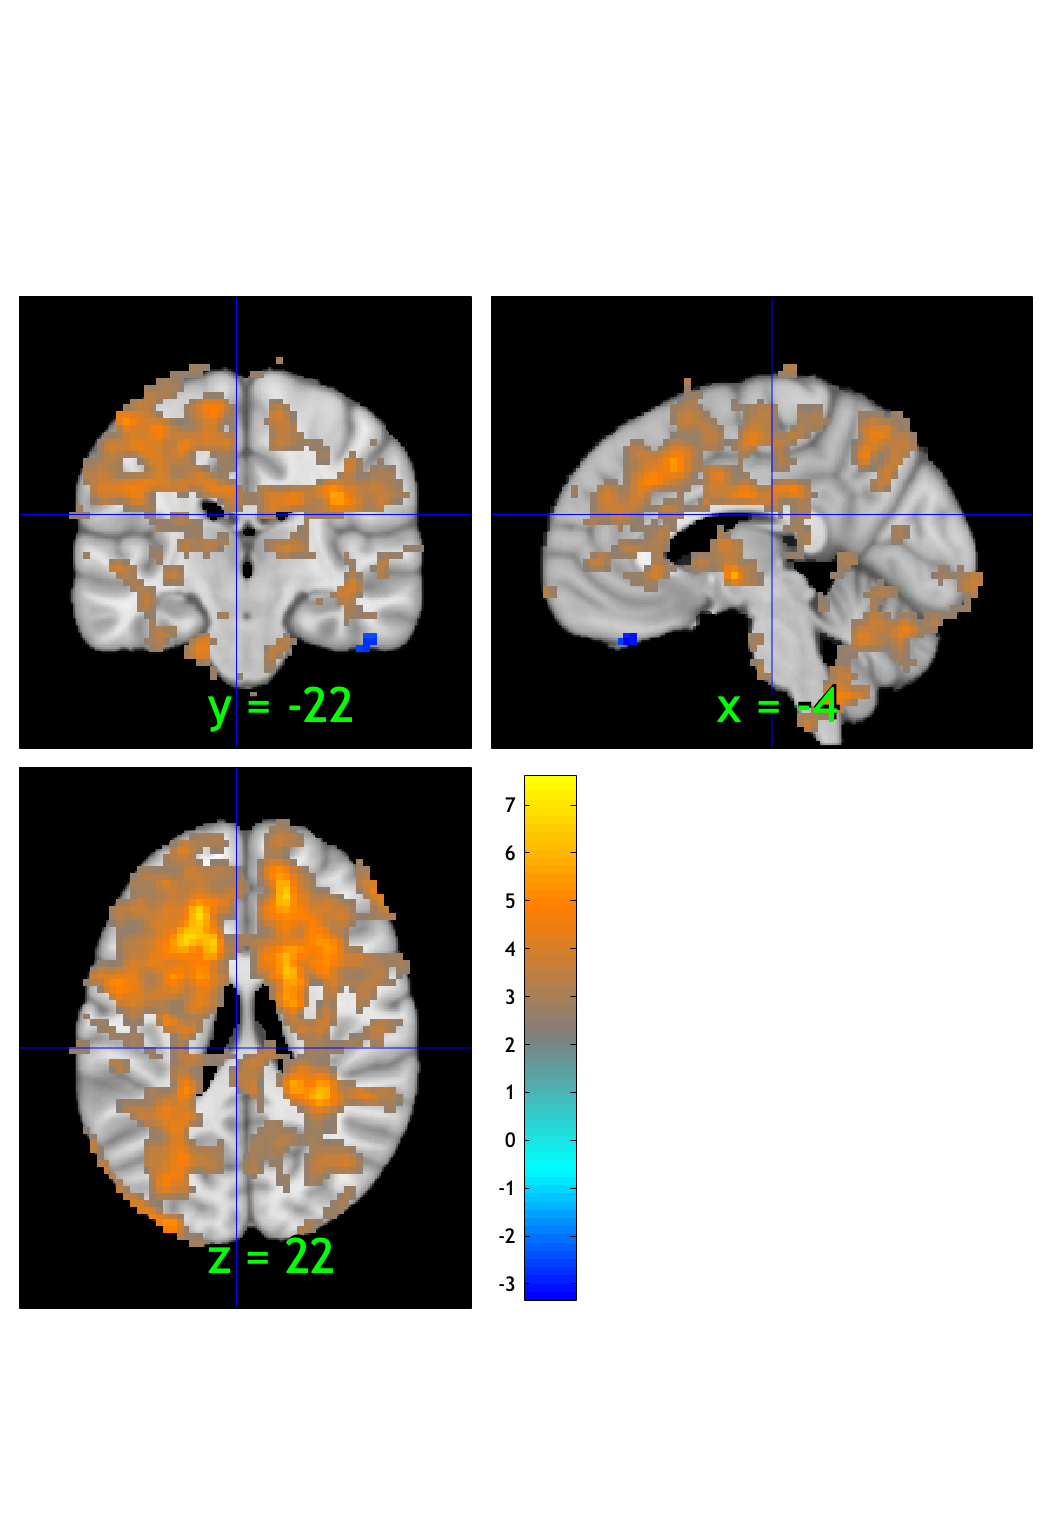

SPM12: spm_check_registration (v7759)              06:53:05 - 26/05/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


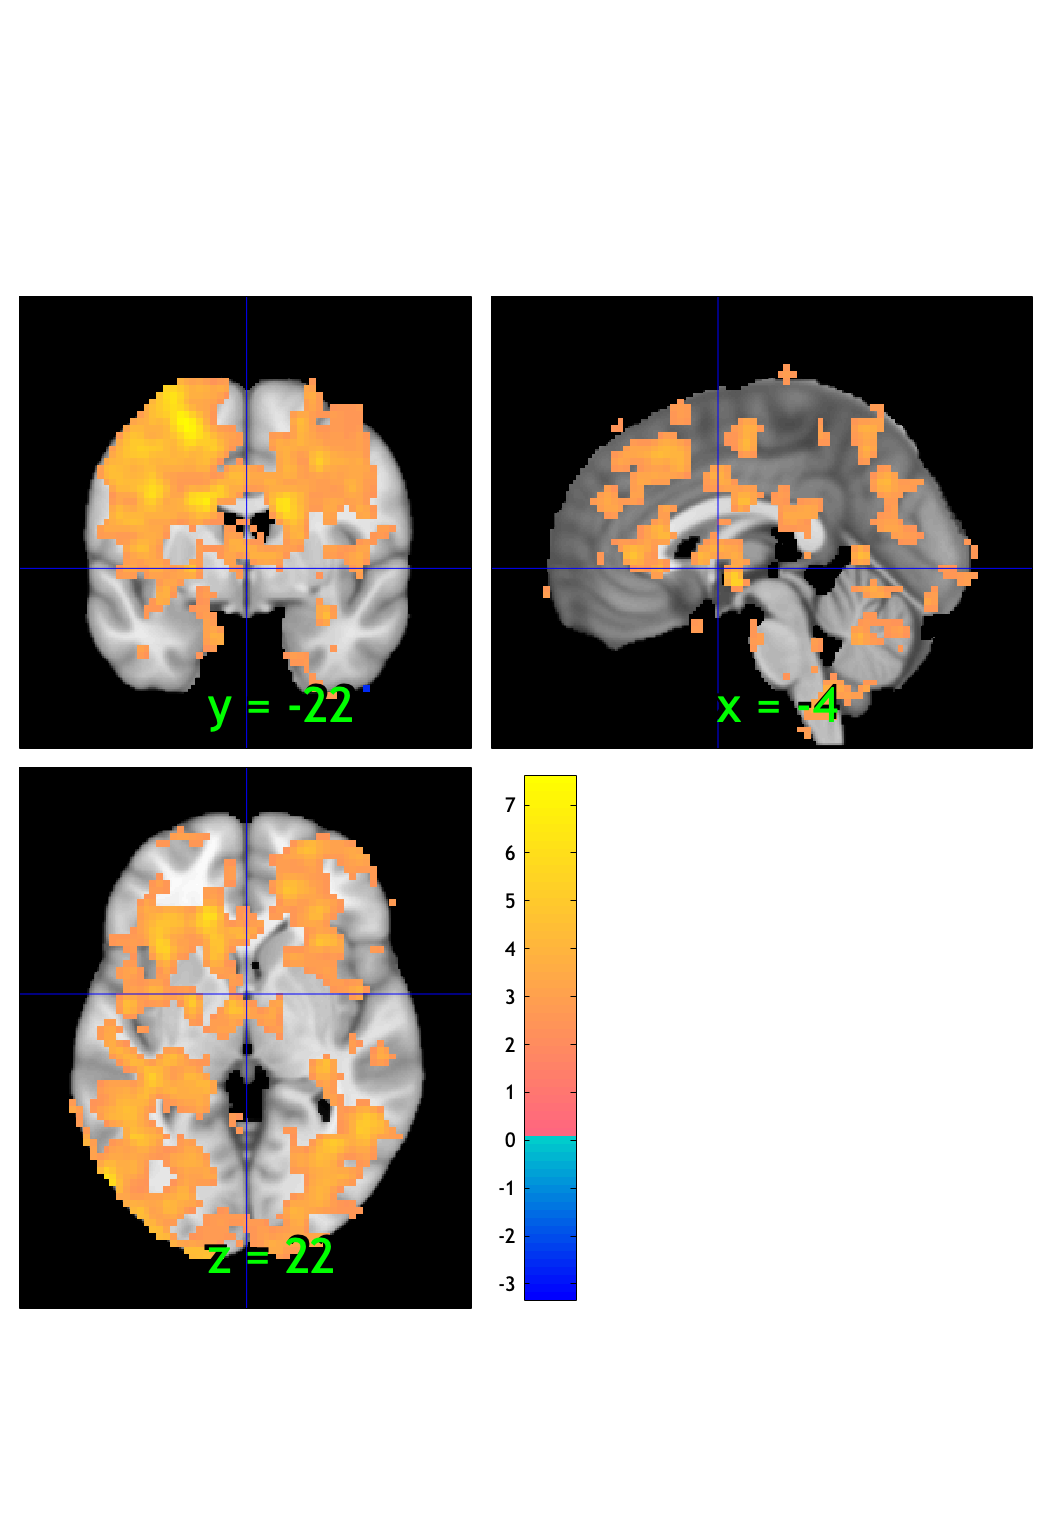

ans = 1×1 cell array
    {1×46 struct}


orthviews(fdr_t)

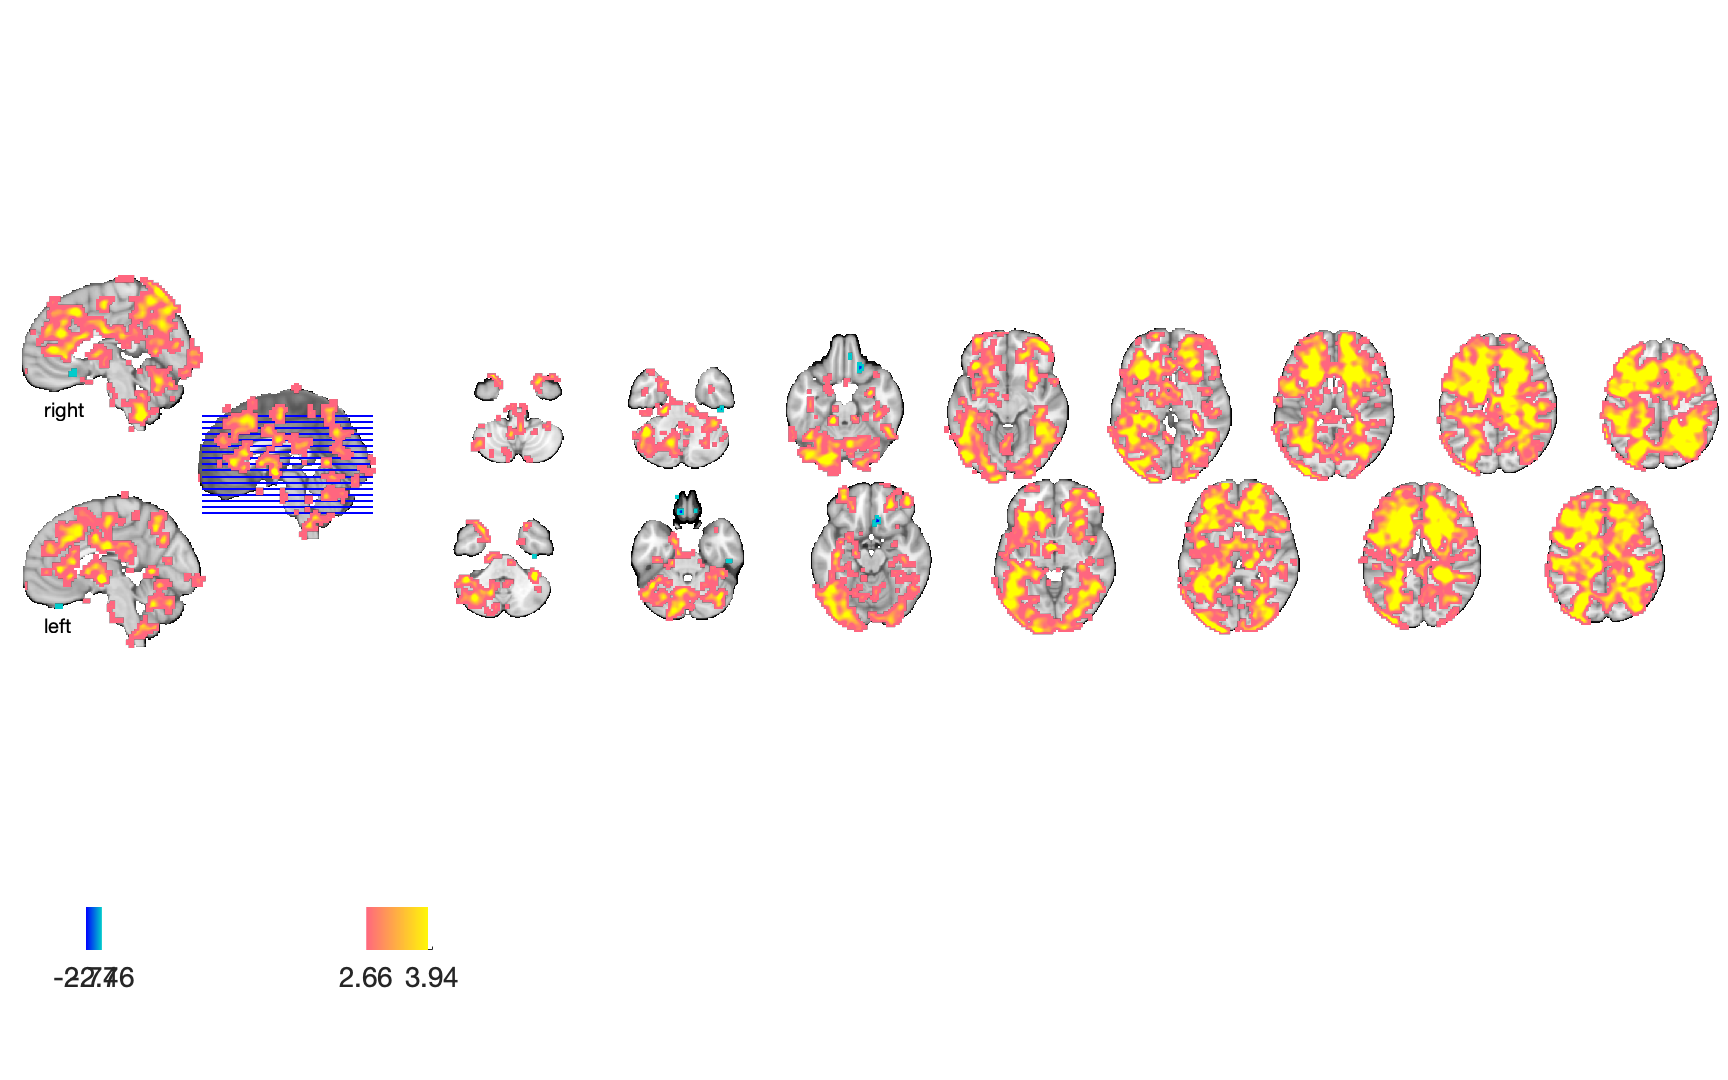

Setting up fmridisplay objects


sagittal montage: 573 voxels displayed, 42701 not displayed on these slices


sagittal montage: 816 voxels displayed, 42458 not displayed on these slices


sagittal montage: 517 voxels displayed, 42757 not displayed on these slices


axial montage: 8228 voxels displayed, 35046 not displayed on these slices


axial montage: 8943 voxels displayed, 34331 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)

drawnow, snapnow;


